# Kitti DataSet localization model

**(Autonomous Vehicle Localization Using Onboard Sensors and HD-Geolocated Maps [MATLAB Project #20] - Spring 2024 Semester).**

[Project Link](https://github.com/mathworks/MATLAB-Simulink-Challenge-Project-Hub/tree/main/projects/Autonomous%20Vehicle%20Localization%20Using%20Onboard%20Sensors%20and%20HD%20Geolocated%20Maps) - [Our submission](https://github.com/Hazem-M-Abdelaziz/Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution/tree/main)

**Presented by: **

- Hazem Mohsen Abdelaziz 

- Yousra Adly Deifallah

**Under Supervision of:**

-  Prof. Mohamed Ibrahim Awad (Head of Mechatronics department - Faculty of Engineering - Ain Shams University)

## Data Loading, Visualization, And Storing.

In this section, dataset paths for Synced and Unsynced are copied into variables to be used in navigating through directories and data extraction later on this live script.

Synced. data path is copied into dataset_path variable, unsynced. is copied into unsyncedDataset_path and the directory which contains the fuzzy systems, evaluation function ("accuracyScore.mlx"), and GPS conversion scripts (from LLA to ENU and vice versa) is copied into mainDirectory variable.

*"when cloning repo, the main directory path should be the KITTI_Localization folder path)"*

%Loading Dataset from extracted folder on our local machine
%Add dataset path below 
dataset_path = 'C:\Users\Hazem Abdelaziz\Downloads\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\KITTI\2011_09_29_drive_0071\2011_09_29_drive_0071_sync';
%Start loading UNSYNC OXTS data to perform same for IMU based estimates
unSyncDataset_path = 'C:\Users\Hazem Abdelaziz\Downloads\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\KITTI\2011_09_29_drive_0071\2011_09_29_drive_0071_extract';
%for GPS data (Where LLA_to_Local function script exists)
mainDirectory = 'C:\Users\Hazem Abdelaziz\Desktop\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\KITTI_Localization';
%Go to images folder and check for how many images in there to represents
%number of frames
rgbFolderPath = strcat(dataset_path, '\image_02\data');
grayFolderPath = strcat(dataset_path, '\image_00\data');
pngFiles = dir(fullfile(rgbFolderPath, '*.png'));
rgbVector = cell(1, numel(pngFiles));
grayVector = cell(1, numel(pngFiles));
%For Unsynced data
unsyncOxtsFolderPath = strcat(unSyncDataset_path, '\oxts\data');
unsyncOxtsFiles = dir(fullfile(unsyncOxtsFolderPath, '*.txt'));
%Setting number of frames and Sampling time according to certain dataset
framesNum = numel(pngFiles);
Ts = 0.1;
%And for Unsynced Data
unsyncFramesNum = numel(unsyncOxtsFiles);
unsyncIMUTs = 0.01;

Following cells are to display first frame from both folders, RGB and Colored.

%Store camera first frame (For center cameras 0: Gray & 2: RGB)
gray_image = imread(fullfile(dataset_path, 'image_00\data', '0000000000.png'));
rgb_image = imread(fullfile(dataset_path, 'image_02\data', '0000000000.png'));

% Display the images
figure;
imshow(gray_image);
title('Gray Scale Image');
figure;
imshow(rgb_image);
title('Colored Image');

Then we extract and store the images from both camera folders into vectors for further processing.

In addition to frames being saved, average intensity per frame is also stored in camAvI vector to be used in cameraWeights_FIS

%Store Colored image in an image vector
% If the data set contains many frames this might take a while
for i = 1:numel(pngFiles)
    %Construct the full file path
    filePath = fullfile(rgbFolderPath, pngFiles(i).name);
    %Read the image and store it
    rgbVector{i} = imread(filePath);
end

%Store Gray image in an image vector
camAvI = zeros(framesNum,1);
for i = 1:numel(pngFiles)
    %Construct the full file path
    filePath = fullfile(grayFolderPath, pngFiles(i).name);
    %Read the image and store it
    grayVector{i} = imread(filePath);
    camAvI(i) = mean(mean(grayVector{i}));
end

The following cell is uncommented to store a video consisting of the consecutive frames obtained from RGB folder for camera 02 (The middle camera)

*to save in a desired directory enter the path to it in the cd command and uncomment its line.*

%This Cell is to save a video consisting of multiple images in a vector
%Each image of type cell
%cd('') %Here you can enter the save location
%{
outputVideo = VideoWriter('output_video.avi'); 
outputVideo.FrameRate = 10; %Frame rate that the images vector recorded at for a better display
open(outputVideo);

for i = 1:numel(rgbVector)
    % Convert image from cell to matrix
    frame =rgbVector{i};
    
    %write the frame to the video
    writeVideo(outputVideo, frame);
end

% Close the video file
close(outputVideo);
cd(mainDirectory);
%}

Displaying the sequence of RGB images using a for loop, with delay between each two consecutive frames given at the end of the loop.

*for faster display, reduce pause inside the for loop.*

%This cell is to display the sequence of rgb colored image frames
for i = 1:numel(rgbVector)
    % Display the current image
    imshow(rgbVector{i});
    title(['Frame ', num2str(i)]); %Adding frame number as a title
    pause(0.1); %Pausing the video according to desired rate 
end

At this stage, for extracting and storing point cloud data from velodyne folder, if the data are not converted and stored in mat format, we uncomment the following cell and if it is already converted from bin to mat, leaving this cell commented is recommended to avoid reconversion.

*If it is the first time using certain dataset, data are stored in bin format so the following cell should be uncommented then commented back after conversion.*

pcdFolderPath = strcat(dataset_path, '\velodyne_points\data');
pcdFiles = dir(pcdFolderPath);
% || CAUTION || %
%This section is to convert from bin file data to 
% !! This section is to be run once to avoid overwriting and saving files
%multiple times, to convert it for the first time uncomment the section
%bellow
%{
cd(pcdFolderPath);
for i = 1:length(pcdFiles)
    filename = pcdFiles(i).name;
    if(length(filename) > 10)
        binOpen = fopen(filename, 'rb'); %Open binary in read mode
        binData = fread(binOpen, [4, inf], 'single')'; %Reading data from binary file
        fclose(binOpen);
        extension_to_remove = '.bin';
        original_str = filename;
        start_idx = strfind(original_str, extension_to_remove);
        end_idx = start_idx + length(extension_to_remove) - 1;
        modified_str = original_str;
        modified_str(start_idx:end_idx) = ''; 
        save(strcat(modified_str,'.mat'), 'binData');
    end
end
%}

Next we visualize first frame point cloud data.

%visualize a LiDAR point cloud from a frame
point_cloud = load(fullfile(pcdFolderPath, '0000000000.mat'));
pcdX = point_cloud.binData(:,1);
pcdY = point_cloud.binData(:,2);
pcdZ = point_cloud.binData(:,3);
point_cloud_data = [pcdX, pcdY, pcdZ];
figure;
pcshow(point_cloud_data)
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Point Cloud Visualization');

To start processing the pcd data, we need to store it into matrix that will hold the characteristics of the frame points detected.

data are stored in matrix with size **P*4*N** as 

**P**: number of points per frame

**N**: Number of frames 

*for each point in P, XYZ position as well as its denormalized intensity are stored in *pcdR* vector, points intensity in pcd is normalized(0-1) so denormalization (0-255) is done before storing to be averaged among whole frame and passed to fuzzy systems later on. *

pcdMat = NaN(5000, 4, framesNum); %This matrix will hold our point cloud
pcdR = zeros(framesNum, 1); %Vector to hold average reflectivity for each frame
matFiles = dir(fullfile(pcdFolderPath, '*.mat'));
for i = 1:numel(matFiles)
    point_cloud = load(fullfile(pcdFolderPath, matFiles(i).name));
    pcdMat(1:length(point_cloud.binData(:,1)),1,i) = point_cloud.binData(:,1);
    pcdMat(1:length(point_cloud.binData(:,2)),2,i) = point_cloud.binData(:,2);
    pcdMat(1:length(point_cloud.binData(:,3)),3,i) = point_cloud.binData(:,3);
    pcdMat(1:length(point_cloud.binData(:,4)),4,i) = point_cloud.binData(:,4) * 255; %Multiplication to get actual value, denormalization  
    pcdR(i) = mean(pcdMat(:,4,i));
    if(i==1)
        fprintf('Out of %d frames, Storing frame No.',numel(matFiles));
    end
    fprintf('\b\b\b\b\b%d', i);
end

To perform point cloud registration, pcd data are downsampled and filtered from any noise after stored in ***pointCloud*** objects to be passed to pcregistericp function.

Downsampling using ***gridAverage*** method breaks down the boundary of pcd data into boxes with size = the number givent to pcdownsample function, then taking average data for points insidde each box to be representing the box with only one point.

the figure below illustrates the process.

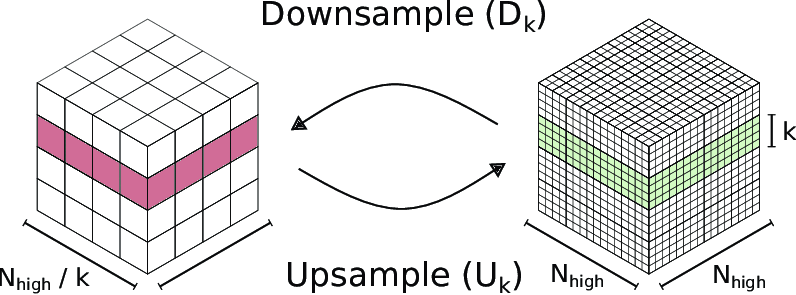

*to perform downsampling, uncomment line that uses pcdownsample adding required side for downsampling*

%Creating point cloud vector to downsample and filter (Preprocessing)
pointCloudObjects = cell(framesNum);
for i = 1:framesNum
    %Convert the array to a pointCloud object
    pointCloudObjects{i} = pointCloud(pcdMat(:,1:3,i));
    pointCloudObjects{i} = pcdownsample(pointCloudObjects{i}, 'gridAverage', 0.25);
    %PCD With noise filtered
    pointCloudObjects{i} = pcdenoise(pointCloudObjects{i}, 'Threshold', 0.5);
    if(i==1)
        fprintf('Out of %d frames, Downsampling and filtering frame No.',framesNum);
    end
    fprintf('\b\b\b\b\b%d', i);
end

Then for displaying pcd data before and after downsampling.

%To display 3D lidar data
xlimits = [-40 40];
ylimits = [-40 40];
zlimits = [ -5 5];
coder.extrinsic('isOpen', 'pcplayer')
player = pcplayer(xlimits, ylimits, zlimits);
for i = 1:numel(matFiles)
    pcdX = pcdMat(:,1,i);
    pcdY = pcdMat(:,2,i);
    pcdZ = pcdMat(:,3,i);
    point_cloud_data = [pcdX, pcdY, pcdZ];
    %Update the plot with the point cloud for the current frame
    view(player, point_cloud_data);
    pause(0.1); %Adjust the pause duration as needed
end

%To display 3D lidar data (Downsampled) and/or filtered
xlimits = [-40 40];
ylimits = [-40 40];
zlimits = [ -5 5];
coder.extrinsic('isOpen', 'pcplayer')
player = pcplayer(xlimits, ylimits, zlimits);
for i = 1:numel(matFiles)
    %Update the plot with the point cloud for the current frame
    view(player, pointCloudObjects{i});
    pause(0.1); %Adjust the pause duration as needed
end

In the following section, we are going to extract data related to IMU and GPS from OXTS folder as data in OXTS files are stored in a certain format defined in dataformat.txt file that can be found in OXTS folder, then data stored in OXTS matrix variable are seperated into vectors for some data to be processed later on.

Finishing this section with visualization for some data.

%Reading GPS/IMU data from OXTS folder
%Data are stored in the format show at dataformat.txt file
oxtsFolderPath = strcat(dataset_path, '\oxts\data');
oxtsFiles = dir(oxtsFolderPath);
cd(oxtsFolderPath);
OXTS = zeros(framesNum,30);
j = 1;
for i = 3:length(oxtsFiles) % 3 to avoid backward in location
    filename = oxtsFiles(i).name;
    if(length(filename) > 5)
        OXTS(j,:) = importdata(filename);
    end
    j = j +1;
end
%Go back to where the live script located to be used in further processing
%for GPS data (Where LLA_to_Local function script exists)
cd(mainDirectory);

%Seperating OXTS folder to Data vectors needed for further processing
%To Get GPS-Based Position(Ground Truth Position)that will be converted to local frame:
latitude = OXTS(:,1);
longitude = OXTS(:,2);
altitude = OXTS(:,3);

%To Get Angles:
roll = OXTS(:,4);
pitch = OXTS(:,5);
yaw = OXTS(:,6);

%To get velocity of vehcile (To evaluate integration model and difference):
vn = OXTS(:,7);
ve = OXTS(:,8);

%IMU Readings (To obtain Pose estimation based on IMU data only):
    %Accelerometer reading:
af = OXTS(:,15);
al = OXTS(:,16);
au = OXTS(:,17);
    %Groscope reading:
wf = OXTS(:,21);
wl = OXTS(:,22);
wu = OXTS(:,23);

%Loading GPS accuracy and numbers of satellites
posAcc = OXTS(:,24);
numSats = OXTS(:,27);

%Creating time frame starting from Second 0 
timeVector = 0:0.1:(framesNum-1)*0.1;

%Get absolute velocity from either derivative of acceleration of
%sqrt(vn^2+ve^2)
vAbs = sqrt(vn.^2 + ve.^2);
%To get the scale factor or abs Dist, that will be used in camera algorithm
%we divide vAbs / camera frequency, which in this case is equals to 10
scaleFactor = vAbs / 10;

%Creating subplots to visualize IMU data
figure;

subplot(3,2,1);
plot(timeVector, af);
xlabel('Time (sec)');
ylabel('Af (m/s^2)');
grid("on");

subplot(3,2,2);
plot(timeVector, al);
xlabel('Time (sec)');
ylabel('Al (m/s^2)');
grid("on");

subplot(3,2,3);
plot(timeVector, au);
xlabel('Time (sec)');
ylabel('Au (m/s^2)');
grid("on");
subplot(3,2,4);
plot(timeVector, wf);
xlabel('Time (sec)');
ylabel('Wf (rad/s)');
grid("on");

subplot(3,2,5);
plot(timeVector, wl);
xlabel('Time (sec)');
ylabel('Wl (rad/s)');
grid("on");

subplot(3,2,6);
plot(timeVector, wu);
xlabel('Time (sec)');
ylabel('Wu (rad/s)');
grid("on");

%Now we plot the route using GPS data on a global map
webmap('Open Street Map');
wmmarker(latitude(1), longitude(1), 'FeatureName', 'Start point'); 
wmline(latitude(2:end-1), longitude(2:end-1)); 
wmmarker(latitude(end), longitude(end), 'FeatureName', 'End point'); 

Next commented cell is used with too noisy IMU data to filter its noise.

%Filtering input data, if needed uncomment below section
%{
Fs = 10; %sampling frequency
%cutoff frequency
cutoff_frequency = 1; % Specify the cutoff frequency for filtering high-frequency noise

%low-pass filter
[b, a] = butter(4, cutoff_frequency / (Fs / 2), 'low'); %4th-order Butterworth filter

% Apply the low-pass filter to the data
af = filtfilt(b, a, af);
al = filtfilt(b, a, al);
wu = filtfilt(b, a, wu);
vn = filtfilt(b, a, vn);
ve = filtfilt(b, a, ve);
%}

%Creating subplots to visualize GPS geodatic frame data
figure;

subplot(1,3,1);
plot(timeVector, latitude);
xlabel('Time (sec)');
ylabel('Latitude (deg)');

subplot(1,3,2);
plot(timeVector, longitude);
xlabel('Time (sec)');
ylabel('Longitude (deg)');

subplot(1,3,3);
plot(timeVector, altitude);
xlabel('Time (sec)');
ylabel('Altitude (m)');

## Loading Unsync Data

As done before with OXTS synced data, same to do with unsynced data from storing into matrix "UNSYNCOXTS" and separating  some data into vectors.

*both **OXTS** and **UNSYNCOXTS** matrices with size **30*F** as *

***F****: synced frames number for **OXTS** or unsynced frames number for **UNSYNCOXTS*

%Reading GPS/IMU data from Unsynchronized OXTS folder
cd(unsyncOxtsFolderPath);
UNSYNCOXTS = zeros(framesNum,30);
j = 1;
for i = 1:length(unsyncOxtsFiles)
    filename = unsyncOxtsFiles(i).name;
    if(length(filename) > 5)
        UNSYNCOXTS(j,:) = importdata(filename);
    end
    j = j +1;
end
%Go back to where the live script located to be used in further processing
%for GPS data (Where LLA_to_Local function script exists)
cd(mainDirectory);

%Separating  OXTS folder to Data vectors needed for further processing
%To Get GPS-Based Position(Ground Truth Position)that will be converted to local frame:
unsyncLatitude = UNSYNCOXTS(:,1);
unsyncLongitude = UNSYNCOXTS(:,2);
unsyncAltitude = UNSYNCOXTS(:,3);

%To Get Unsynced Angles:
unsyncRoll = UNSYNCOXTS(:,4);
unsynchPitch = UNSYNCOXTS(:,5);
unsyncYaw = UNSYNCOXTS(:,6);

%To get velocity of vehcile (To evaluate integration model and difference):
unsyncVn = UNSYNCOXTS(:,7);
unsyncVe = UNSYNCOXTS(:,8);

%IMU Readings (To obtain Pose estimation based on IMU data only):
    %Accelerometer reading:
unsyncAf = UNSYNCOXTS(:,15);
unsyncAl = UNSYNCOXTS(:,16);
unsyncAu = UNSYNCOXTS(:,17);
    %Groscope reading:
unsyncWf = UNSYNCOXTS(:,21);
unsyncWl = UNSYNCOXTS(:,22);
unsyncWu = UNSYNCOXTS(:,23);

%Loading GPS accuracy and numbers of satellites
unsyncPosAcc = UNSYNCOXTS(:,24);
unsyncNumSats = UNSYNCOXTS(:,27);

%Creating time frame starting from Second 0 (Assuming Ts is const at 0.01s)
unsyncTimeVector = 0:0.01:(unsyncFramesNum-1)*0.01;

### GPS data conversion (Geodatic to local) and Visualization

As GPS data extracted from both synced and unsynced data are stored in LLA coordinate system frame, we convert both into local ENU frame to be compared with different sensor-based localization models upcoming.

%Converting LLA cordinate frame position to Local frame position using GPS
%data obtained
GPSn = zeros(framesNum, 1);
GPSe = zeros(framesNum, 1);
unsyncGPSn = zeros(unsyncFramesNum, 1);
unsyncGPSe = zeros(unsyncFramesNum, 1);
%Refrencing motion to first frame readings
for i= 1:framesNum
    [deltaE, deltaN, ~] = lla_to_enu(latitude(1), longitude(1), altitude(1), latitude(i), longitude(i), altitude(i));
    GPSe(i) = deltaE;
    GPSn(i) = deltaN;
end
for i= 1:unsyncFramesNum
    [deltaE, deltaN, ~] = lla_to_enu(unsyncLatitude(1), unsyncLongitude(1), unsyncAltitude(1), unsyncLatitude(i), unsyncLongitude(i), unsyncAltitude(i));
    unsyncGPSe(i) = deltaE;
    unsyncGPSn(i) = deltaN;
end

%Graph GPS based position
figure;

plot(GPSe, GPSn, '-o');
hold on;
plot(unsyncGPSe, unsyncGPSn, '-*');

xlabel('East position (m)');
ylabel('North Position (m)');
legend('Synced GPS position', 'UnSynced GPS position');
grid on;

## **IMU Based Localization**

First of all, data stored from OXTS folder into vectors, they are stored wrt vehicle frame, in the first cell we are converting acceleration values for vehicle frame (Front, Left, and Up) to local frame (East, North, and Up) with the help of vehicle orientation.

Then data converted into local frame stored as East Acceleration (Ae), North Acceleration (An), and Angular velocity in Upward direction (Wu) are passed to integrator model to obtain 2D vehicle pose following these equations, a*ssuming constant angular velocity in upward direction (Angular_Acceleration_Upward = 0).*

**Ts**: sampling time

Then output from discrete integration model is graphed and compared with GPS obtained data.

*Previous steps are done for both synced and unsynced data with taking into consideration sampling time difference but Ts is considered as const in both 0.1 for synced and 0.01 for unsynced .*

### Synced IMU-Based Localization model, evaluation, and Stored data visualization

%Convert Acceleration from sensor frame (Vehicle frame) to Global ENU Frame
Avehicle = [af,al];
Aenu = zeros(framesNum,2);
for i= 1:framesNum
    Aenu(i,1) = (cos(yaw(i)) * af(i)) -(sin(yaw(i)) * al(i));
    Aenu(i,2) = (sin(yaw(i)) * af(i)) +(cos(yaw(i)) * al(i));
end
Ae = Aenu(:,1);
An = Aenu(:,2);

%To get IMU-Based Pose: 
IMUYaw = zeros(framesNum, 1);
IMUn= zeros(framesNum,1);
IMUe= zeros(framesNum,1);
IMUVn = zeros(framesNum,1);
IMUVe = zeros(framesNum,1);

%Setting initial data
IMUYaw(1) = yaw(1);
IMUVn(1) = vn(1);
IMUVe(1) = ve(1);

%Assuming zero initial pose.
for i = 2:(framesNum)
    %Using double integration to get position from acceleration and single step integration to get orientation from angular velocity
    IMUVn(i) = IMUVn(i-1) + (An(i) * Ts); %Velociy from integration (north direction)
    IMUVe(i) = IMUVe(i-1) + (Ae(i) * Ts); %Velociy from integration (east direction)

    IMUn(i) = IMUn(i-1) + (IMUVn(i) * Ts) + (0.5 * (Ts^2) * An(i)); %Position from integration (north direction)
    IMUe(i) = IMUe(i-1) + (IMUVe(i) * Ts) + (0.5 * (Ts^2) * Ae(i)); %Position from integration (east direction)

    IMUYaw(i) = IMUYaw(i-1) + (wu(i) * Ts); %orientation from integration (Yaw angle)
end    

%Evaluating IMU-Based Position based on Ground truth data
figure;

subplot(2, 1, 1);
plot(GPSe, GPSn, '-o');
hold on;
plot(IMUe, IMUn, '-*');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('Synced GPS route', 'Synceed IMU route');
grid on;

subplot(2, 1, 2);
plot(timeVector, rad2deg(yaw), 'g');
hold on;
plot(timeVector, rad2deg(IMUYaw), 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (deg)');
legend('Ground-Truth Yaw', 'IMU-Based Yaw');
grid on;
sgtitle('IMU-Based model output');

%Calculating Error (Difference between IMU and GPS data)
SeDiff = GPSe - IMUe;
SnDiff = GPSn- IMUn;
yawDiff = rad2deg(yaw- IMUYaw);

%Graphing error
figure;
figure('Position', [50, 50, 600, 600]); % [left bottom width height]

subplot(3, 1, 1);
plot(timeVector, SeDiff, 'r');
xlabel('Time (s)');
ylabel('Se difference (m)');
grid on;
subplot(3, 1, 2);
plot(timeVector, SnDiff, 'g');
xlabel('Time (s)');
ylabel('Sn difference (m)');
grid on;
subplot(3, 1, 3);
plot(timeVector, yawDiff, 'b');
xlabel('Time (s)');
ylabel('Yaw angle difference (deg)');
title('Yaw Angle')
grid on;

sgtitle('IMU-Based model Difference to GPS');

### [Unsynchronized] IMU-Based Localization model, evaluation, and Stored data visualization

%Convert Acceleration from sensor frame (Vehicle frame) to Global ENU Frame
unsyncAvehicle = [unsyncAf,unsyncAl];
unsyncAenu = zeros(unsyncFramesNum,2);
for i= 1:unsyncFramesNum
    unsyncAenu(i,1) = (cos(unsyncYaw(i)) * unsyncAf(i)) -(sin(unsyncYaw(i)) * unsyncAl(i));
    unsyncAenu(i,2) = (sin(unsyncYaw(i)) * unsyncAf(i)) +(cos(unsyncYaw(i)) * unsyncAl(i));
end
unsyncAe = unsyncAenu(:,1);
unsyncAn = unsyncAenu(:,2);

%To get Unsync IMU-Based Pose: 
unsyncIMUYaw = zeros(unsyncFramesNum, 1);
unsyncIMUn= zeros(unsyncFramesNum,1);
unsyncIMUe= zeros(unsyncFramesNum,1);
unsyncIMUVn = zeros(unsyncFramesNum,1);
unsyncIMUVe = zeros(unsyncFramesNum,1);

%Setting initial data
unsyncIMUYaw(1) = unsyncYaw(1);
unsyncIMUVn(1) = unsyncVn(1);
unsyncIMUVe(1) = unsyncVe(1);

%Assuming zero initial pose.
for i = 2:(unsyncFramesNum)
    %Using double integration to get position from acceleration and single
    %step integration to get o
    % rientation from angular velocity
    unsyncIMUVn(i) = unsyncIMUVn(i-1) + (unsyncAn(i) * unsyncIMUTs); %Velociy from integration (north direction)
    unsyncIMUVe(i) = unsyncIMUVe(i-1) + (unsyncAe(i) * unsyncIMUTs); %Velociy from integration (east direction)

    unsyncIMUn(i) = unsyncIMUn(i-1) + (unsyncIMUVn(i) * unsyncIMUTs); %Position from integration (north direction)
    unsyncIMUe(i) = unsyncIMUe(i-1) + (unsyncIMUVe(i) * unsyncIMUTs); %Position from integration (east direction)

    unsyncIMUYaw(i) = unsyncIMUYaw(i-1) + (unsyncWu(i) * unsyncIMUTs); %orientation from integration (Yaw angle)
end

%Evaluating IMU-Based Position based on Ground truth data
figure;

subplot(2, 1, 1);
plot(unsyncGPSe, unsyncGPSn, '-o');
hold on;
plot(unsyncIMUe, unsyncIMUn, '-*');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('unSynced GPS route', 'unSynceed IMU route');
grid on;

subplot(2, 1, 2);
plot(unsyncTimeVector, unsyncYaw, 'g');
hold on;
plot(unsyncTimeVector, unsyncIMUYaw, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'IMU-Based Yaw');
grid on;
sgtitle('Unsynced IMU-Based model output');

%Calculating Error (Difference between Unsync IMU and GPS data)
unsyncSeDiff = unsyncGPSe - unsyncIMUe;
unsyncSnDiff = unsyncGPSn - unsyncIMUn;
unsyncYawDiff = rad2deg(unsyncYaw - unsyncIMUYaw);


%Graphing error
figure;
subplot(3, 1, 1);
plot(unsyncTimeVector, unsyncSeDiff, 'r');
xlabel('Time (s)');
ylabel('Unsync Se difference (m)');
grid on;
subplot(3, 1, 2);
plot(unsyncTimeVector, unsyncSnDiff, 'r');
xlabel('Time (s)');
ylabel('Unsync Sn difference (m)');
grid on;
subplot(3, 1, 3);
plot(unsyncTimeVector, unsyncYawDiff, 'r');
hold on;
xlabel('Time (s)');
ylabel('Unsync Yaw angle difference (deg)');
title('Yaw Angle')
grid on;

sgtitle('Unsynced IMU-Based model Difference to GPS');

## Lidar-Based Localization model and evaluation

Here for Lidar-Based localization model, we use synced lidar data to be registered using certain metric (pointToPoint, pointToPlane, planeToPlane, etc..) to estimate relative pose between two consecutive frames

In referencing the pcd data to local reference frame, we use lidar Yaw estimated as well as IMU referenced yaw angle as an integration between lidar and IMU data to perform a better Lidar-Based localization.

Lets say that difference matching icp approaches or metric used follow the same steps as following.

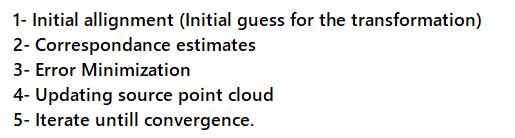

but to differentiate between approach and another, step 2 and 3 differ according to matching metric used.

then at the end of this section, results are graphed compared to GPS data as well as difference between lidar-based approach and GPS data with and without integrating with the angle from IMU module.

*As yaw angle is embedded in the calculation for referencing the relative pose for the local frame, we use lidar angle as well as IMU angle in Lidar-INS referenced approach for estimating the pose as the INS according to different data processing provides more accurate angles.*

lidarX = zeros(1, framesNum);
lidarY = zeros(1, framesNum);
lidarXBar = zeros(1, framesNum);
lidarYBar = zeros(1, framesNum);
lidarYaw = zeros(1, framesNum);
lidarYaw(1) = rad2deg(yaw(1)); %Setting initial starting angle
lidarSampleNumber = framesNum-1; 
transformations = zeros(4,4,framesNum);
transformations(:,:,1) = eye(4);
for i = 1:lidarSampleNumber %for more accurate (full trajectory results we need to change from a limited number to total number of frames)
    %Check if each point cloud has at least three unique points
    ptCloudOne= pointCloudObjects{i};
    ptCloudTwo = pointCloudObjects{i+1};
    numptCloudOne = size(ptCloudOne.Location, 1);
    numptCloudTwo = size(ptCloudTwo.Location, 1);
    if numptCloudOne < 3 || numptCloudTwo < 3
        lidarX(i+1) = lidarX(i);
        lidarY(i+1) = lidarY(i);
        lidarXBar(i+1) = lidarXBar(i);
        lidarYBar(i+1) = lidarYBar(i);
        lidarYaw(i+1) = lidarYaw(i);
    else
        [tform, ~, ~] = pcregistericp(ptCloudTwo, ptCloudOne, Metric="planeToPlane");
        %Extract rotation matrix and translation vector from transformation matrix
        R = tform.T(1:3, 1:3);
        eulerAngles = -rotm2eul(R, 'XYZ');
        deltaYaw_vehicle_deg = double(rad2deg(eulerAngles(3)));
        t = tform.T(4, 1:3)';
        deltaY_vehicle_m =  (t(1) * sin(deg2rad(lidarYaw(i)))) - (t(2) * cos(deg2rad(lidarYaw(i)))); %for only lidar data
        deltaX_vehicle_m = - (t(2) * sin(deg2rad(lidarYaw(i)))) + (t(1) * cos(deg2rad(lidarYaw(i)))); %for only lidar data
        deltaY_vehicle_mBar =  (t(1) * sin(IMUYaw(i))) - (t(2) * cos(IMUYaw(i))); %for Lidar-INS referenced
        deltaX_vehicle_mBar = - (t(2) * sin(IMUYaw(i))) + (t(1) * cos(IMUYaw(i))); %for Lidar-INS referenced
        lidarY(i+1) = lidarY(i) + deltaY_vehicle_m;
        lidarX(i+1) = lidarX(i) + deltaX_vehicle_m;
        lidarYBar(i+1) = lidarYBar(i) + deltaY_vehicle_mBar;
        lidarXBar(i+1) = lidarXBar(i) + deltaX_vehicle_mBar;
        lidarYaw(i+1) = lidarYaw(i) + deltaYaw_vehicle_deg;
        transformations(:,:,i+1) = (tform.A);
    end
    %Display number of iteration to see current progress
    if(i==1)
        fprintf('Out of %d frames, Processing point cloud matching on frame No.',framesNum);
    end
    fprintf('\b\b\b\b\b%d', i+1);
end

%Evaluating Lidar-Based Position based on Ground truth data
figure;

subplot(2, 1, 1);
plot(unsyncGPSe, unsyncGPSn, '-o');
hold on;
plot(lidarX, lidarY, '-*');
plot(lidarXBar, lidarYBar, '-s');

xlabel('East position (m)');
ylabel('North Position (m)');
legend('Synced GPS route', 'Lidar route', 'Lidar INS referenced route');
grid on;

subplot(2, 1, 2);
plot(timeVector, yaw, 'g');
hold on;
plot(timeVector, deg2rad(lidarYaw), 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'IMU-Based Yaw');
grid on;
sgtitle('Unsynced IMU-Based model output');

sgtitle('Lidar-Based model output');

%Calculating Error (Difference between Lidar and GPS data)
LidarXDiff = GPSe - (lidarX)';
LidarYDiff = GPSn - (lidarY)';
LidarXBarDiff = GPSe - (lidarXBar)';
LidarYBarDiff = GPSn - (lidarYBar)';
LidaryawDiff = rad2deg(yaw) - (lidarYaw)';

%Graphing error
figure;
subplot(3,1,1);
plot(timeVector, LidarXDiff, '-o');
hold on;
plot(timeVector, LidarXBarDiff, '-*');
xlabel('Time (sec)');
ylabel('X Error (m)');
legend('Lidar X error', 'Lidar-INS Referenced X error');
grid("on");

subplot(3,1,2);
plot(timeVector, LidarYDiff, '-o');
hold on;
plot(timeVector, LidarYBarDiff, '-*');
xlabel('Time (sec)');
ylabel('Y Error (m)');
legend('Lidar Y error', 'Lidar-INS Referenced Y error');
grid("on");

subplot(3,1,3);
plot(timeVector,  LidaryawDiff);
xlabel('Time (sec)');
ylabel('Yaw difference (deg)');
grid("on");
sgtitle('Lidar-Based model difference to GPS');

### Point Cloud map

Now we construct point cloud map from data obtained and with help of our lidar-based model output to accumulate point cloud data per frame; to visualize the scene in form of point cloud map.

Sequence of constructing point cloud map:

1- Read point cloud data per frame wrt sensor location

2- Transform data to map origin (Sensor location at the start of the data [Frame 0])

        when transforming point cloud data we extract points locations and convert them to homogeneous to multiply them by transformation matrix [We stored before when performing icp registration] in order to transform them to the first frame before accumulation as described below.

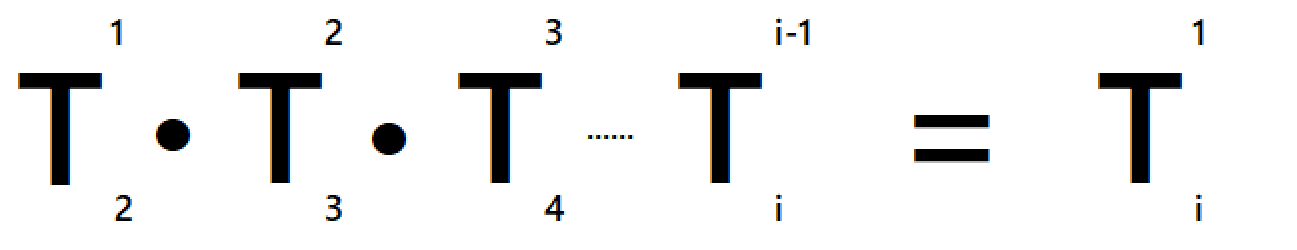

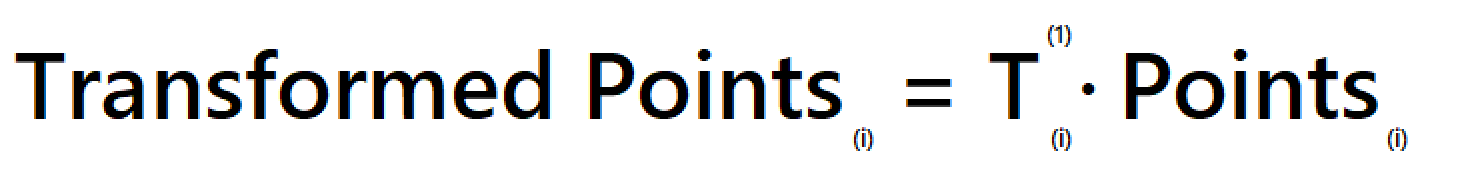

3- Accumulate point cloud location into point cloud object to hold the point cloud map of the run.

*You can adjust downsampling for processing power and time consumption  and also to adjust the view of the point cloud map and how many points in it, just uncoment lines with downsampling and comment the ones without!*

%Initializing an empty point cloud.
%downsamplingSize = 0.1;
%combinedPointCloud = pcdownsample(pointCloudObjects{i}, 'gridAverage', downsamplingSize);
combinedPointCloud = pointCloudObjects{1};
lidarYawDiff = cumsum(diff(lidarYaw));
transformationMatrix = eye(4);
%Looping through each frame and accumulate points.
for i = 2:framesNum

    pointCloudObjects{i} = pointCloud(pcdMat(:,1:3,i));
    %currentFrame = pcdownsample(pointCloudObjects{i}, 'gridAverage', downsamplingSize);
    currentFrame = pointCloudObjects{i};

    %Extraction locations of points that are new to map only 
    points = currentFrame.Location;

    %converting points to homogenious points
    homogeneousPoints = [points, ones(size(points, 1), 1)];
    
    transformationMatrix = transformationMatrix * transformations(:,:,i);
    
    %Applying transformation
    transformedPointsHomogeneous = (transformationMatrix * homogeneousPoints')';

    %Convering points back to cartesian for accumulation and converting back to point cloud object
    transformedPtCloud = pointCloud(transformedPointsHomogeneous(:, 1:3));


    %Accumulating current points to previous points
    combinedPointCloud = pcmerge(combinedPointCloud, transformedPtCloud, 0.1); %Merge with tolerance.

    if(i==2)
        fprintf('Out of %d frames, Accumulating frame No.',framesNum);
    end
    fprintf('\b\b\b\b\b%d', i);

end

figure;
pcdMapX = combinedPointCloud.Location(:,1);
pcdMapY = combinedPointCloud.Location(:,2);
pcdMapZ = combinedPointCloud.Location(:,3);
point_cloud_map = [pcdMapX, pcdMapY, pcdMapZ];
pcshow(point_cloud_map)
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Point Cloud Map Visualization');

## Camera-Based Localization model and evaluation

In camera-based localization, we start with identifying camera parameters, that could be found in calibration files.

Then we start loop for camera pose estimation that follows the following sequence.

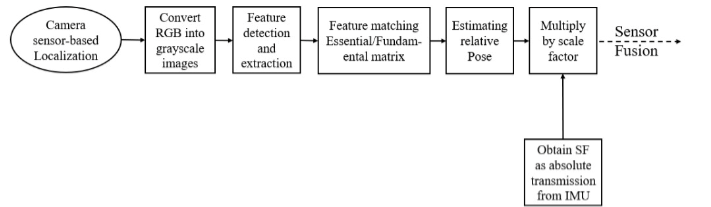

And multiplying by scale factor (Absolute motion obtained by IMU integrator model to find abs distance between two frames), as we use estrelpose function that return translation normalized between frames.

After obtaining camera-based pose, we graph results in comparison with GPS provided data as well as the difference.

*For limited number of features uncoment lines that indentify points1 and points2 with selectStrongest and comment the ones without.*

*To visualize matched frames, Uncomment showMatchedFeatures line.*

%Creating cameraParams object
%See cam_to_cam_calib file to obtain these values
focalLength = [984 980];
principalPoint = [690 233];
cameraParams = cameraIntrinsics(focalLength, principalPoint, size(grayVector{1}(:,:,1)));

%Loop for saving camera estimates
camX = zeros(1,numel(pngFiles));
camY = zeros(1,numel(pngFiles));
camYaw = zeros(1,numel(pngFiles));
camYaw(1) = yaw(1);
figure;
for i = 1:numel(pngFiles) - 1

    grayFrame1 = grayVector{i};
    grayFrame2 = grayVector{i+1};

    %Detect and match features
    %For limited number of features
    %points1 = selectStrongest(detectKAZEFeatures(grayFrame1), 500);
    %points2 = selectStrongest(detectKAZEFeatures(grayFrame2), 500);

    %For maximum number of features
    points1 = detectKAZEFeatures(grayFrame1);
    points2 = detectKAZEFeatures(grayFrame2);

    [features1, points1] = extractFeatures(grayFrame1, points1);
    [features2, points2] = extractFeatures(grayFrame2, points2);

    indexPairs = matchFeatures(features1, features2);
    matchedPoints1 = points1(indexPairs(:, 1), :);
    matchedPoints2 = points2(indexPairs(:, 2), :);

    % Estimate Fundamental/Essential matrix
    [eMatrix, inliers] = estimateEssentialMatrix(matchedPoints1, matchedPoints2, cameraParams);

    % Select inlier points
    inlierPoints1 = matchedPoints1(inliers);
    inlierPoints2 = matchedPoints2(inliers);

    %Estimate relative camera pose
    relPose = estrelpose(eMatrix, cameraParams, inlierPoints1, inlierPoints2);

    Rot = relPose.R;
    t = relPose.Translation;

    eulerAngles = rotm2eul(Rot, 'XYZ');
    camYaw(i+1) = camYaw(i) - eulerAngles(2); 
    camX(i+1) = camX(i) + t(3)*cos(yaw(i+1))*scaleFactor(i) - t(1)*sin((pi/2)-yaw(i+1))*scaleFactor(i);
    camY(i+1) = camY(i) + t(3)*sin(yaw(i+1))*scaleFactor(i) - t(1)*cos((pi/2)-yaw(i+1))*scaleFactor(i);

    %Visualize matched features
    %showMatchedFeatures(grayFrame1, grayFrame2, inlierPoints1, inlierPoints2, 'montage');
    if(i==1)
        fprintf('Out of %d frames, features matching on frame No.',framesNum);
    end
    fprintf('\b\b\b\b\b%d', i+1);    
end

figure;
subplot(2, 1, 1);
plot(GPSe, GPSn, '-o');
hold on;
plot(camX, camY, '-*');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('GPS route', 'Camera route');
grid on;

subplot(2, 1, 2);
plot(timeVector, yaw, 'g');
hold on;
plot(timeVector, camYaw, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Camera-Based Yaw');
grid on;
sgtitle('Camera-Based model output');

%camera based error evaluation
%Calculating Error (Difference between Camera and GPS data)
SeDiffCam = GPSe' - camX;
SnDiffCam = GPSn'- camY;
yawDiffCam = rad2deg(yaw' - camYaw);

%Graphing error
figure;
subplot(3, 1, 1);
plot(timeVector, SeDiffCam, 'r');
xlabel('Time (s)');
ylabel('Se difference (m)');
grid on;
subplot(3, 1, 2);
plot(timeVector, SnDiffCam, 'g');
xlabel('Time (s)');
ylabel('Sn difference (m)');
grid on;
subplot(3, 1, 3);
plot(timeVector, yawDiffCam, 'b');
xlabel('Time (s)');
ylabel('Yaw angle difference (deg)');
title('Yaw Angle')
grid on;

sgtitle('Camera-Based model Difference to GPS');

## Table of comparison for each sensor-based localization approach

In this section, we are going to compare results obtained from sensor-based localization model for each of the given sensor and compare it to the given GPS data as ground truth.

We construct table of comparison includes sensor used, max deviation in local east position, max deviation in local north position, and maximum deviation in yaw angle.

***Note****: This comparison does not include accuracy of the GPS data stored.*

names = {'Synced IMU', 'unSynced IMU' 'Synced Camera', 'Synced Lidar'};
maxEastDeviation = [max(abs(SeDiff)), max(abs(unsyncSeDiff)), max(abs(SeDiffCam)), max(abs(LidarXBarDiff))];
maxNorthDeviation = [max(abs(SnDiff)), max(abs(unsyncSnDiff)), max(abs(SnDiffCam)), max(abs(LidarYBarDiff))];
maxYawDeviation = [max(abs(yawDiff)), max(abs(unsyncYawDiff)), max(abs(yawDiffCam)), max(abs(LidaryawDiff))];
sensorBasedTable = table(names', maxEastDeviation', maxNorthDeviation', maxYawDeviation','VariableNames',{'Sensor used', 'Max. deviation in East(m)', 'Max deviation in North(m)', 'Max deviation in Yaw(deg)'})

## **Sensory Data Fusion**

After obtaining data from each sensor individually, we try to fuse data to get our best estimate.

In the following section, we are trying multiple methods (Adaptive and non-adaptive) filters to get sound pose estimates.

### Average Estimation Model

In the first non-adaptive method, we use data obtained before in sensor-based localization models from each sensor individually and average the reading of them all to see how to model will perform in comparison with GPS data taking into consediration position accuracy of the given GPS module.

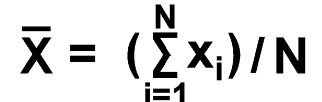

The previous formula dedescribes the behavior of the average model as:

N = 4 (Number of sensors).

x̄: pose extracted from each sensor.

then we graph data of obtained model as well as difference between GPS data, for comparison with GPS data consediring position accuracy see last section (Accuracy Score).

XAvg = zeros(framesNum, 1);
YAvg = zeros(framesNum, 1);
YawAvg = zeros(framesNum, 1);

for i= 1:framesNum
    XAvg(i) = (camX(:,i) + lidarXBar(:,i) + GPSe(i,:) + IMUe(i,:)) / 4;
    YAvg(i) = (camY(:,i) + lidarYBar(:,i) + GPSn(i,:) + IMUn(i,:)) / 4;
    YawAvg(i) = (camYaw(:,i) + deg2rad(lidarYaw(:,i)) + yaw(i,:) + IMUYaw(i,:)) / 4;
end

%Graphing Average Estimation output in comparison with GPS data as the ground truth
figure;

subplot(2, 1, 1);
plot(GPSe, GPSn, '-o');
hold on;
plot(XAvg, YAvg, '-*');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('GPS route', 'Average Estimation route');
grid on;

subplot(2, 1, 2);
plot(timeVector, yaw, 'g');
hold on;
plot(timeVector, YawAvg, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Average Estimation Yaw');
grid on;
sgtitle('Average Estimation model output');

%AV Using synced data evaluation
AEDeltaE = GPSe - XAvg;
AEDeltaN = GPSn - YAvg;
AEDeltaYaw = rad2deg(yaw - YawAvg);

figure;

subplot(3, 1, 1);
plot(timeVector, AEDeltaE, 'r');
xlabel('Time (s)');
ylabel('Error in East (m)');
grid on;

subplot(3, 1, 2);
plot(timeVector, AEDeltaN, 'g');
xlabel('Time (s)');
ylabel('KF_North/GPS North (m)');
ylabel('Error in North (m)');
grid on;

subplot(3, 1, 3);
plot(timeVector, AEDeltaYaw, 'b');
xlabel('Time (s)');
ylabel('Error in Yaw (deg)');
grid on;
sgtitle('Average Estimation Model output Difference to GPS');

### Weighted Sum Estimation

For the second non-adaptive method we use similar formula for average model but adding weights to every sensor, these weights might be representative of sensor reading quality but here they are constant along the path.

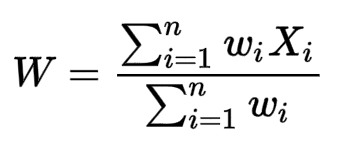

previous formula will be used two times, firstly with consediring GPS data in the filter, and secondly neglecting GPS data to see how the rest of the sensors will behave in predecting the vehicle states.

Then the output of both methods are graphed to visualize the output.

XGWs = zeros(framesNum, 1);
YGWs = zeros(framesNum, 1);
YawGWs = zeros(framesNum, 1);
X = [camX', lidarXBar', GPSe, IMUe];
Y = [camY', lidarYBar', GPSn, IMUn];
Yaw = [camYaw', deg2rad(lidarYaw)', yaw, IMUYaw];
WeigthGXY = [5, 10, 20, 20];
WeigthGYaw = [5, 8, 20, 10];

for i= 1:framesNum
    XGWs(i,:) = sum(WeigthGXY .* X(i,:)) / sum(WeigthGXY);
    YGWs(i,:) = sum(WeigthGXY .* Y(i,:)) / sum(WeigthGXY);
    YawGWs(i,:) = sum(WeigthGYaw .* Yaw(i,:)) / sum(WeigthGYaw);
end

%Graphing Weighted Sum Estimation Including GPS output in comparison with GPS data as the ground truth
figure;

subplot(2, 1, 1);
plot(GPSe, GPSn, '-o');
hold on;
plot(XGWs, YGWs, '-*');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('GPS route', 'Weighted sum route');
grid on;

subplot(2, 1, 2);
plot(timeVector, yaw, 'g');
hold on;
plot(timeVector, YawGWs, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Weighted sum route');
grid on;
sgtitle('Weighted sum model output');

%GWS data difference
GWSDeltaE = GPSe - XGWs;
GWSDeltaN = GPSn - YGWs;
GWSDeltaYaw = rad2deg(yaw - YawGWs);

figure;

subplot(3, 1, 1);
plot(timeVector, GWSDeltaE, 'r');
xlabel('Time (s)');
ylabel('Error in East (m)');
grid on;

subplot(3, 1, 2);
plot(timeVector, GWSDeltaN, 'g');
xlabel('Time (s)');
ylabel('Error in North (m)');
grid on;

subplot(3, 1, 3);
plot(timeVector, GWSDeltaYaw, 'b');
xlabel('Time (s)');
ylabel('Error in Yaw (deg)');
grid on;
sgtitle('Weighted Sum Estimation Including GPS output evaluation');

XWs = zeros(framesNum, 1);
YWs = zeros(framesNum, 1);
YawWs = zeros(framesNum, 1);
WeigthXY = [5, 10, 0, 20];
WeigthYaw = [5, 8, 0, 10];

for i= 1:framesNum
    XWs(i,:) = sum(WeigthXY .* X(i,:)) / sum(WeigthXY);
    YWs(i,:) = sum(WeigthXY .* Y(i,:)) / sum(WeigthXY);
    YawWs(i,:) = sum(WeigthYaw .* Yaw(i,:)) / sum(WeigthYaw);
end

%Graphing Weighted Sum Estimation Without GPS output in comparison with GPS data as the ground truth
figure;

subplot(2, 1, 1);
plot(GPSe, GPSn, '-o');
hold on;
plot(XWs, YWs, '-*');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('GPS route', 'Weighted sum excluding GPS data route');
grid on;

subplot(2, 1, 2);
plot(timeVector, yaw, 'g');
hold on;
plot(timeVector, YawWs, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Weighted sum route');
grid on;

sgtitle('Weighted Sum Estimation Without GPS output');

%WS data difference
WSDeltaE = GPSe - XWs;
WSDeltaN = GPSn - YWs;
WSDeltaYaw = rad2deg(yaw - YawWs);

figure;

subplot(3, 1, 1);
plot(timeVector, WSDeltaE, 'r');
xlabel('Time (s)');
ylabel('Error in East (m)');
grid on;

subplot(3, 1, 2);
plot(timeVector, WSDeltaN, 'g');
xlabel('Time (s)');
ylabel('Error in North (m)');
grid on;

subplot(3, 1, 3);
plot(timeVector, WSDeltaYaw, 'b');
xlabel('Time (s)');
ylabel('Error in Yaw (deg)');
grid on;
sgtitle('Weighted Sum Estimation Without GPS difference to GPS');

### Standard Kalman Filter

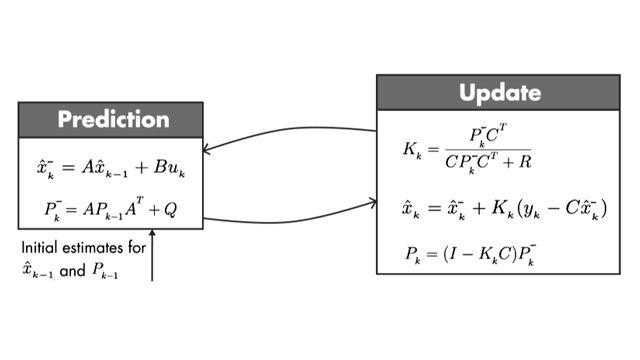

As  seen in previous figure, KF mainly consists of two phases, Prediction in which we used IMU data model to predict vehicle state.

but first of all we need to specify the filter states which are [X Y Vx Vy Yaw]'.

and update step depends on whether we use synced or unsynced data, which later we will discuss both to see the difference. 

*Initial estimates of any data set as [0 0] local position to simplify comparison, but then this local position will be converted again to global LLA system referencing to first point coordinates extracted before from OXTS folder.*

NOTE: in non-adaptive filters, Process noise covariance matrix and Measurements noise covariance matrix contains constant value along the path.

#### Synced data Kalman Filter

In synced KF, we have the readings of 4 sensors in synchronization so we use IMU data in prediction phase and the rest of the sensors (Camera, GPS, and Lidar) in update phase.

as data in prediction are ready from sensor-based step before in [X Y Yaw]' format, we use Measurement matrix as follows:

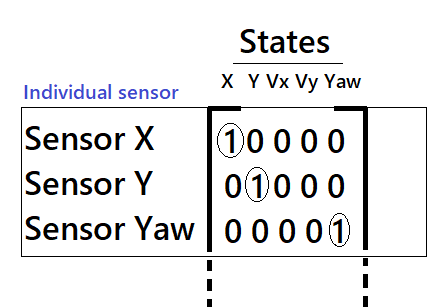

each sensor measurements are in order inside Y vector (Input measurements to filter) will have three columns to map measurements to states as described above, so in synced KF we use H matrix with size 9x3.

at the end of this section we can see.

%Now with all data stored and set to be used in evaluating different filters estimates.
%Using Kalman Filter as follows (Initialzing Parameters and matrices (dt, F, G, H, Q, R) -> Setting Initial estimates -> Main Loop (Prediction -> update))

%1- Initialzing Parameters and Matrices (Synced data)
dt = 0.1; %Time step for used synced data approximately.
%Initializing State Transition matrix (F)
F = [1, 0, dt, 0, 0;
     0, 1, 0, dt, 0;
     0, 0, 1, 0, 0;
     0, 0, 0, 1, 0;
     0, 0, 0, 0, 1];
%Initializing Control Matrix (G)
G = [(dt^2)/2, 0, 0;
     0, (dt^2)/2, 0;
     dt, 0, 0;
     0, dt, 0;
     0, 0, dt];
%Initializing Measurements matrix (H)
H = [1, 0, 0, 0, 0;
     0, 1, 0, 0, 0;
     0, 0, 0, 0, 1;
     1, 0, 0, 0, 0;
     0, 1, 0, 0, 0;
     0, 0, 0, 0, 1;
     1, 0, 0, 0, 0;
     0, 1, 0, 0, 0;
     0, 0, 0, 0, 1];
%Initializing Process noise covariance matrix (Q)
Q = diag([0.1, 0.1, 0.01, 0.01, 0.1]);
%Initializing Measurement noise covariance matrix (R) for every sensor
R = diag([0.2, 0.2, 0.2, 0.1, 0.1, 0.1, 0.01, 0.01, 0.01]); %CAMERA -> LIDAR -> GPS
%2-Setting initial estimates
%Initializing variables vector to hold xCheck, xHat, pCheck, pHat
xCheck = zeros(framesNum+1,5,1)';
pCheck = zeros(framesNum+1,5,5);
xHat = zeros(framesNum+1,5,1)'; % (+1) for inital estimates -> xHat(0)
pHat = zeros(framesNum+1,5,5); % (+1) for inital estimates -> pHat(0)
K = zeros(framesNum+1,5,9);
%Initializing state estimates xHat(k-1) -> first prediction iteration
xHat(:,1) = zeros(5,1); %[GPSe(0); GPSn(0); ve(0); vn(0); yaw(0);]; -> are all assumed to be zero
xHat(5,1) = yaw(1);
%Initializing error covariance estimates pHat(k-1) -> first prediction iteration
pHat(1,:,:) = eye(5);
%Input matrix
u = [Ae An wu]';
%Measurement Matrix y
y = zeros(9, framesNum+1);
y(:,2:end) = [camX' camY' camYaw' lidarXBar' lidarYBar' deg2rad(lidarYaw') GPSe GPSn yaw]'; %to store input with size with size 9*numFrames

%3.0-Main filter loop
for i = 2:framesNum +1
%Prediction step
xCheck(:,i) = (F * xHat(:,i-1)) + (G * u(:,i-1));
pCheck(i,:,:) = (F * reshape(pHat(i-1,:,:), 5, 5) * F') + Q;
%Update step -> proceeed update step in 3 stages ->
K(i,:,:) = (reshape(pCheck(i,:,:), 5, 5) * H') * (inv(((H *reshape(pCheck(i,:,:), 5, 5) * H') + R)));
xHat(:,i) = xCheck(:,i) + reshape(K(i,:,:), 5, 9)*(y(:,i) - (H * xCheck(:,i)));
pHat(i,:,:) = (eye(5) - (reshape(K(i,:,:), 5, 9) * H)) * reshape(pCheck(i,:,:),5, 5);
end

%Seperating 2D Pose from states for visualization
kfEast = xHat(1, 2:end);
kfNorth = xHat(2, 2:end);
kfYaw = xHat(5, 2:end);
%Graphing Filter output in comparison with GPS data as the ground truth
figure;

subplot(2, 1, 1);
plot(GPSe, GPSn, '-o');
hold on;
plot(kfEast, kfNorth, '-*');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('GPS route', 'Kalman Filter route');
grid on;

subplot(2, 1, 2);
plot(timeVector, yaw, 'g');
hold on;
plot(timeVector, kfYaw, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Kalman Filter route');
grid on;

sgtitle('Synced KF output');

%KF Using synced data difference
kfDeltaE = GPSe - kfEast';
kfDeltaN = GPSn - kfNorth';
kfDeltaYaw = rad2deg(yaw - kfYaw');

figure;

subplot(3, 1, 1);
plot(timeVector, kfDeltaE, 'r');
xlabel('Time (s)');
ylabel('Error in East (m)');
grid on;

subplot(3, 1, 2);
plot(timeVector, kfDeltaN, 'g');
xlabel('Time (s)');
ylabel('Error in North (m)');
grid on;

subplot(3, 1, 3);
plot(timeVector, kfDeltaYaw, 'b');
xlabel('Time (s)');
ylabel('Error in Yaw (deg)');
grid on;
sgtitle('Synced KF output difference to GPS');

#### Unsynced data Kalman Filter

In unsynced KF, we use same prediction phase as synced KF, but in update phase, we enter the update loop with sensors that already sent data before next prediction; if IMU sent data we predict and wait untill another sensor send, if only GPS sends data we update according to GPS only, if GPS, Camera, and Lidar send data we update according to all 3 sensors.

Data arrangement while using KITTI is done using timestamp files for each sensor, each sensor has its timestamp file that tells us when the sensor sent its data; so we extract time vector for each sensor to be as indicator in entering different phases of the filter.

Here we extract timestamps for unsynced oxts and synced Camera and lidar and referencing time to the first OXTS reading as it is (high frequency module) and storing that time series into vectors to be indication while entering different unsynced KF phases.

*In the next section we can see that we have extracted time of camera and lidar in one step as we are using synced camera and lidar data as they are (low frequency sensors).*

*But as first unsynced frame might not be synced, so we need to know the first synced frame to unsynced data and add updated states to all synced readings to match filter process.*

%Extracting time for camera, lidar, and (IMU & GPS).

%Creating timeSeries from timestamps text file for oxts data
uOxtsTsPath = strcat(unSyncDataset_path, '\oxts\', 'timestamps.txt');
fid = fopen(uOxtsTsPath, 'r');
timestamps_str = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
timestampsOXTS = datetime(timestamps_str{1}, 'InputFormat', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS', 'Format', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS');

%For camera timestamps
camTsPath = strcat(dataset_path, '\image_00\', 'timestamps.txt');
fid = fopen(camTsPath, 'r');
timestamps_str = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
timestampsCAMERA = datetime(timestamps_str{1}, 'InputFormat', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS', 'Format', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS');

%For lidar timestamps
lidarTsPath = strcat(dataset_path, '\velodyne_points\', 'timestamps_end.txt');
fid = fopen(lidarTsPath, 'r');
timestamps_str = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
timestampsLIDAR = datetime(timestamps_str{1}, 'InputFormat', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS', 'Format', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS');

%Referencing timevectors to first OXTS timestamp.
OXTSTseries = cumsum(seconds(diff(timestampsOXTS)));
CAMERATseries = seconds(timestampsCAMERA - timestampsOXTS(1));
LIDARTseries = seconds(timestampsLIDAR - timestampsOXTS(1));

Next we start identifying constants fot the models to be used in main loop phases.

%Initialzing Parameters and Matrices (UnSynced data)
dtU = 0.01; %Time step for used unsynced data approximately.
%Initializing State Transition matrix (F)
FU = [1,     0,      dtU,     0,      0;
      0,     1,      0,      dtU,     0;
      0,     0,      1,      0,       0;
      0,     0,      0,      1,       0;
      0,     0,      0,      0,       1];
%Initializing Control Matrix (G)
GU = [(dtU^2)/2,      0,                  0;
      0,             (dtU^2)/2,           0;
      dtU,            0,                  0;
      0,             dtU,                 0;
      0,             0,                 dtU];

%Initializing Measurements matrix (H) -> Including only one sensor
Hindividual = [1,     0,      0,      0,      0;
               0,     1,      0,      0,      0;
               0,     0,      0,      0,      1];

%Initializing Measurements matrix (H) -> Including two sensor
Hdouble = [Hindividual; Hindividual];

%Initializing Process noise covariance matrix (Q)
QU = diag([0.1, 0.1, 0.01, 0.01, 0.1]);
%Initializing Measurement noise covariance matrix (R) for every sensor
Rindividual = diag([0.01, 0.01, 0.01]); %GPS
RCamGPS = diag([0.2, 0.2, 0.2, 0.01, 0.01, 0.01]); %Camera and GPS
RLidarGPS = diag([0.1, 0.1, 0.1, 0.01, 0.01, 0.01]); %Lidar and GPS
%Initializing variables vector to hold xCheck, xHat, pCheck, pHat
xCheckUG = zeros(unsyncFramesNum+1,5,1)';
pCheckUG = zeros(unsyncFramesNum+1,5,5);
xHatUG = zeros(unsyncFramesNum+1,5,1)'; % (+1) for inital estimates -> xHat(0)
pHatUG = zeros(unsyncFramesNum+1,5,5); % (+1) for inital estimates -> pHat(0)
%Initializing state estimates xHat(k-1) -> first prediction iteration
xHatUG(5,1) = unsyncYaw(1); %[GPSe(0); GPSn(0); ve(0); vn(0); yaw(0);]; -> are all assumed to be zero not including yaw
%Initializing error covariance estimates pHat(k-1) -> first prediction iteration
pHatUG(1,:,:) = eye(5);
%Input matrix 
uU = [unsyncAe unsyncAn unsyncWu];

%Main filter loop for unsynced data
syncedFrameCAM = 1;
syncedFrameLIDAR = 1;
unsyncedFrame = 1; % i - 1
firstMatchL = find(OXTSTseries >= LIDARTseries(1), 1); %First match for Lidar
firstMatchC = find(OXTSTseries >= CAMERATseries(1), 1); %First match for Camera
for i = 2:unsyncFramesNum+1
    %Prediction step
    xCheckUG(:,i) = (FU * xHatUG(:,i-1)) + (GU * uU(unsyncedFrame,:)');
    pCheckUG(i,:,:) = (FU * reshape(pHatUG(unsyncedFrame,:,:), 5, 5) * FU') + QU;
    %Update step
    %When Camera and lidar data are taken into consideration with GPS (All sends data at the same time).
    if(((syncedFrameCAM < framesNum) && (syncedFrameLIDAR < framesNum)) && (LIDARTseries(syncedFrameLIDAR) <= OXTSTseries(unsyncedFrame)) && (CAMERATseries(syncedFrameCAM) == LIDARTseries(syncedFrameLIDAR)))
        %Now Set R, H, and Y --> to suit Lidar, Camera, GPS
        Y = [camX(syncedFrameCAM)+xHatUG(1,firstMatchC) camY(syncedFrameCAM)+xHatUG(2,firstMatchC) camYaw(syncedFrameCAM) lidarXBar(syncedFrameLIDAR)+xHatUG(1,firstMatchL) lidarYBar(syncedFrameLIDAR)+xHatUG(2,firstMatchL) deg2rad(lidarYaw(syncedFrameLIDAR)) unsyncGPSe(unsyncedFrame) unsyncGPSn(unsyncedFrame) unsyncYaw(unsyncedFrame)]';
        K = (reshape(pCheckUG(i,:,:), 5, 5) * H') * (inv(((H * reshape(pCheckUG(i,:,:), 5, 5) * H') + R)));
        xHatUG(:,i) = xCheckUG(:,i) + K*(Y - (H * xCheckUG(:,i)));
        pHatUG(i,:,:) = (eye(5) - K * H) * reshape(pCheckUG(i,:,:), 5, 5);
        syncedFrameLIDAR = syncedFrameLIDAR + 1;
        syncedFrameCAM = syncedFrameCAM + 1;
        
    %this if one of the sensors camera or lidar sends data not both at the same time.
    elseif ((syncedFrameCAM < framesNum) || (syncedFrameLIDAR < framesNum)) && ((LIDARTseries(syncedFrameLIDAR) <= OXTSTseries(unsyncedFrame)) || (CAMERATseries(syncedFrameCAM) <= OXTSTseries(unsyncedFrame)))
         
        %Update for lidar and GPS
        if (LIDARTseries(syncedFrameLIDAR) <= OXTSTseries(unsyncedFrame))
            Y = [lidarXBar(syncedFrameLIDAR)+xHatUG(1,firstMatchL) lidarYBar(syncedFrameLIDAR)+xHatUG(2,firstMatchL) deg2rad(lidarYaw(syncedFrameLIDAR)) unsyncGPSe(unsyncedFrame) unsyncGPSn(unsyncedFrame) unsyncYaw(unsyncedFrame)]';
            K = (reshape(pCheckUG(i,:,:), 5, 5) * Hdouble') * (inv(((Hdouble * reshape(pCheckUG(i,:,:), 5, 5) * Hdouble') + RLidarGPS)));
            xHatUG(:,i) = xCheckUG(:,i) + K*(Y - (Hdouble * xCheckUG(:,i)));
            pHatUG(i,:,:) = (eye(5) - K * Hdouble) * reshape(pCheckUG(i,:,:), 5, 5);
            syncedFrameLIDAR = syncedFrameLIDAR + 1;
        end
        %Update for camera and GPS
        if (CAMERATseries(syncedFrameCAM) <= OXTSTseries(unsyncedFrame))
            Y = [camX(syncedFrameCAM)+xHatUG(1,firstMatchC) camY(syncedFrameCAM)+xHatUG(2,firstMatchC) camYaw(syncedFrameCAM) unsyncGPSe(unsyncedFrame) unsyncGPSn(unsyncedFrame) unsyncYaw(unsyncedFrame)]';
            K = (reshape(pCheckUG(i,:,:), 5, 5) * Hdouble') * (inv(((Hdouble * reshape(pCheckUG(i,:,:), 5, 5) * Hdouble') + RCamGPS)));
            xHatUG(:,i) = xCheckUG(:,i) + K*(Y - (Hdouble * xCheckUG(:,i)));
            pHatUG(i,:,:) = (eye(5) - K * Hdouble) * reshape(pCheckUG(i,:,:), 5, 5);
            syncedFrameCAM = syncedFrameCAM + 1;
        end

    %Update using only GPS
    else
        Y = [unsyncGPSe(unsyncedFrame) unsyncGPSn(unsyncedFrame) unsyncYaw(unsyncedFrame)]';
        K = (reshape(pCheckUG(i,:,:), 5, 5) * Hindividual') * (inv(((Hindividual * reshape(pCheckUG(i,:,:), 5, 5) * Hindividual') + Rindividual)));
        xHatUG(:,i) = xCheckUG(:,i) + K*(Y - (Hindividual * xCheckUG(:,i)));
        pHatUG(i,:,:) = (eye(5) - K * Hindividual) * reshape(pCheckUG(i,:,:), 5, 5);
    end
    unsyncedFrame = unsyncedFrame + 1;
end

%Seperating 2D Pose from states for visualization
kfEastU = xHatUG(1,2:end);
kfNorthU = xHatUG(2,2:end);
kfYawU = xHatUG(5,2:end);
%Graphing Filter output in comparison with GPS data as the ground truth
figure;
subplot(2, 1, 1);
plot(unsyncGPSe, unsyncGPSn, '--');
hold on;
plot(kfEastU, kfNorthU, '--');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('GPS route', 'Unsynced Kalman Filter route');
grid on;

subplot(2, 1, 2);
plot(unsyncTimeVector', unsyncYaw, 'g');
hold on;
plot(unsyncTimeVector, kfYawU, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Unsynced Kalman Filter route');
grid on;

sgtitle('UnSynced KF output');

figure;
%KF Using unsynced data 
kfDeltaEU = unsyncGPSe - kfEastU';
kfDeltaNU = unsyncGPSn - kfNorthU';
kfDeltaYawU = rad2deg(unsyncYaw - kfYawU');

figure;

subplot(3, 1, 1);
plot(unsyncTimeVector, kfDeltaEU', 'r');
xlabel('Time (s)');
ylabel('Error in East (m)');
grid on;

subplot(3, 1, 2);
plot(unsyncTimeVector, kfDeltaNU', 'g');
xlabel('Time (s)');
ylabel('KF_North/GPS North (m)');
ylabel('Error in North (m)');
grid on;

subplot(3, 1, 3);
plot(unsyncTimeVector, kfDeltaYawU', 'b');
xlabel('Time (s)');
ylabel('Error in Yaw (deg)');
grid on;
sgtitle('unSynced data KF error difference to GPS');

## Extracting Weights for adaptive filters

Now for the adaptive filters, after storing data needed to enter fuzzy inference systems to decide sensors depedability, we pass the data to get depedability per frame for each sensor as follows.

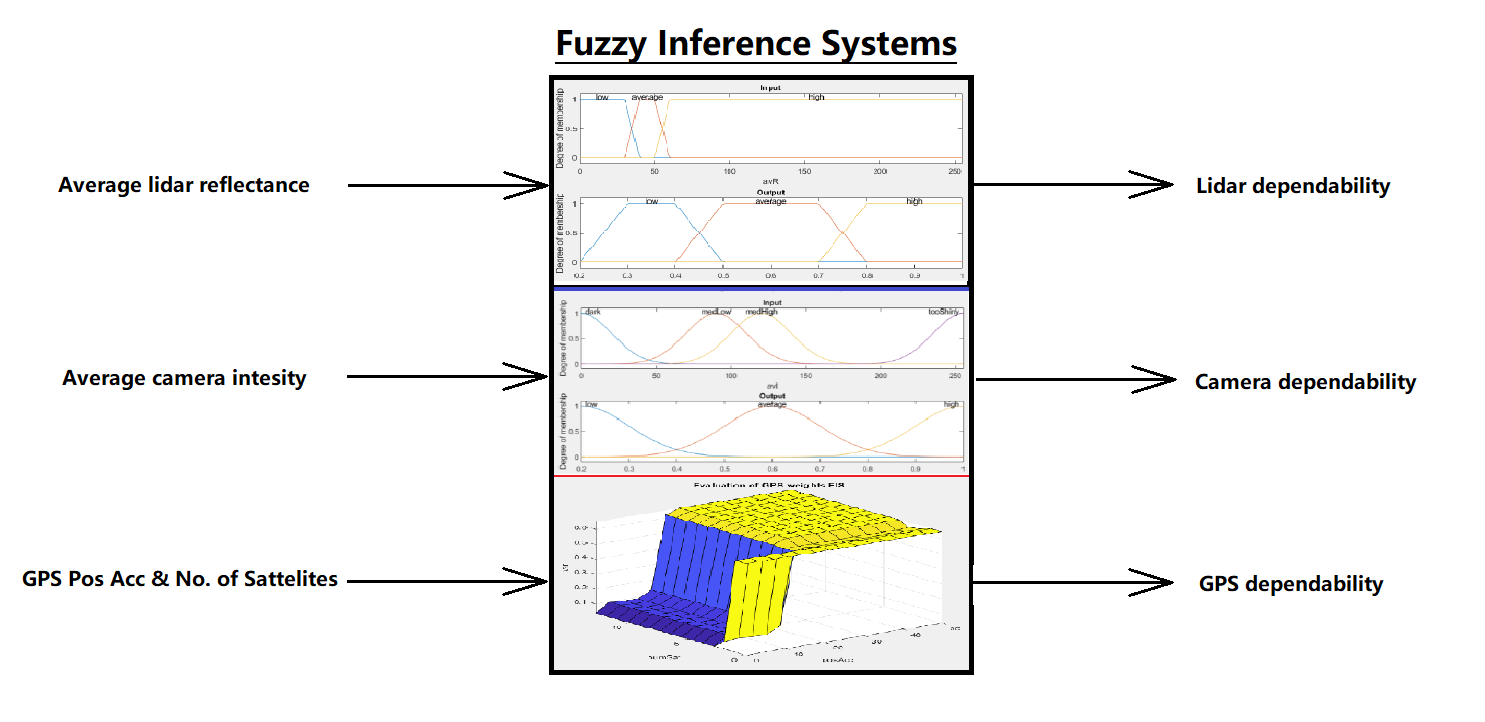

*For more details and/or modifications on fuzzy systems, see (gpsWeights_FIS, camWeights_FIS, and lidarWeights_FIS). in main directory mentioned before.*

%First extracting Synced data weights for camera, lidar, and gps
gpsVar = (gpsWeights_FIS([posAcc numSats])).^2;
unsyncGpsVar = (gpsWeights_FIS([unsyncPosAcc unsyncNumSats])).^2;
camVar = (camWeights_FIS(camAvI)).^2;
lidarVar = (lidarWeights_FIS(pcdR)).^2;
imuVar = (0.25 * ones(framesNum, 1)).^2;%as imu weight and it is constant

%Plotting Weights for adaptive filters
figure;
plot(timeVector, gpsVar, '-o');
hold on;
plot(unsyncTimeVector, unsyncGpsVar, '-*');
plot(timeVector, camVar, '-x');
plot(timeVector, lidarVar, '-s');
plot(timeVector, imuVar, '-g');
legend('Synced GPS Variance', 'Unsynced GPS Variance', 'Camera Variance', 'Lidar Variance', 'IMU Variance');
title('Different sensors variance based on fuzzy inference systems');
xlabel('Time (s)');
ylabel('Variance');
grid on;
hold off;

*After extracting weights per frame, we pass weights to different techniques as (weights in weighted average filter, process noise covariance matrix and measurements noise covariance matrix in KF approaches).*

## Adaptive filters (Weighted Average - KF - unsynced KF).

### Adaptive Weighted Average Model

XAGWs = zeros(framesNum, 1);
YAGWs = zeros(framesNum, 1);
YawAGWs = zeros(framesNum, 1);
X = [camX', lidarXBar', GPSe, IMUe];
Y = [camY', lidarYBar', GPSn, IMUn];
Yaw = [camYaw', deg2rad(lidarYaw)', yaw, IMUYaw];
WeigthsAvModel = [(1 ./ camVar) (1 ./ lidarVar) (1 ./ gpsVar) (1 ./ imuVar)];

for i= 1:framesNum
    XAGWs(i,:) = sum(WeigthsAvModel(i,:) .* X(i,:)) / sum(WeigthsAvModel(i,:));
    YAGWs(i,:) = sum(WeigthsAvModel(i,:) .* Y(i,:)) / sum(WeigthsAvModel(i,:));
    YawAGWs(i,:) = sum(WeigthsAvModel(i,:) .* Yaw(i,:)) / sum(WeigthsAvModel(i,:));
end

%Graphing Filter output in comparison with GPS data as the ground truth
figure;
subplot(2, 1, 1);
plot(GPSe, GPSn, '--');
hold on;
plot(XAGWs, YAGWs, '--');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('GPS route', 'Adaptive weighted average route');
grid on;

subplot(2, 1, 2);
plot(timeVector', yaw, 'g');
hold on;
plot(timeVector, YawAGWs, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Adaptive weighted average route');
grid on;

sgtitle('Adaptive Weighted average output');

%Adaptive weighted average Using synced data difference
AWADeltaE = GPSe - XAGWs;
AWADeltaN = GPSn - YAGWs;
AWADeltaYaw = rad2deg(yaw - YawAGWs);

figure;

subplot(3, 1, 1);
plot(timeVector, AWADeltaE, 'r');
xlabel('Time (s)');
ylabel('Error in East (m)');
grid on;

subplot(3, 1, 2);
plot(timeVector, AWADeltaN, 'g');
xlabel('Time (s)');
ylabel('Error in North (m)');
grid on;

subplot(3, 1, 3);
plot(timeVector, AWADeltaYaw, 'b');
xlabel('Time (s)');
ylabel('Error in Yaw (deg)');
grid on;
sgtitle('Adaptive weighted average output difference to GPS');

### Adaptive Kalman Filter

%Storing R values 
AR = ones(9,9,framesNum);
imuVariance = imuVar(1);
for i = 1:framesNum
    AR(:,:,i) = diag([camVar(i), camVar(i), camVar(i), lidarVar(i), lidarVar(i), lidarVar(i), gpsVar(i), gpsVar(i), gpsVar(i)]); %Camera - lidar - gps
end
camRMatrix = AR(1:3, 1:3, :);
lidarRMatrix = AR(4:6, 4:6, :);

%Initializing parameters.
AQ = diag([imuVariance, imuVariance, imuVariance^0.5, imuVariance^0.5, imuVariance]);
AxCheck = zeros(framesNum+1,5,1)';
ApCheck = zeros(framesNum+1,5,5);
AxHat = zeros(framesNum+1,5,1)'; % (+1) for inital estimates -> xHat(0)
ApHat = zeros(framesNum+1,5,5); % (+1) for inital estimates -> pHat(0)
AK = zeros(framesNum+1,5,9);
%Initializing state estimates xHat(k-1) -> first prediction iteration
AxHat(:,1) = zeros(5,1); %[GPSe(0); GPSn(0); ve(0); vn(0); yaw(0);]; -> are all assumed to be zero
AxHat(5,1) = yaw(1);
%Initializing error covariance estimates pHat(k-1) -> first prediction iteration
ApHat(1,:,:) = eye(5);
%applying same Kalman main loop but with adaptive weights
for i = 2:framesNum +1
    %Prediction step
    AxCheck(:,i) = (F * AxHat(:,i-1)) + (G * u(:,i-1));
    ApCheck(i,:,:) = (F * reshape(ApHat(i-1,:,:), 5, 5) * F') + AQ;
    %Update step -> proceeed update step in 3 stages ->
    AK(i,:,:) = (reshape(ApCheck(i,:,:), 5, 5) * H') * (inv(((H *reshape(ApCheck(i,:,:), 5, 5) * H') + reshape(AR(:,:,i-1), 9,9))));
    AxHat(:,i) = AxCheck(:,i) + reshape(AK(i,:,:), 5, 9)*(y(:,i) - (H * AxCheck(:,i)));
    ApHat(i,:,:) = (eye(5) - (reshape(AK(i,:,:), 5, 9) * H)) * reshape(ApCheck(i,:,:),5, 5);
end
AkfEast = AxHat(1, 2:end);
AkfNorth = AxHat(2, 2:end);
AkfYaw = AxHat(5, 2:end);

%Graphing Filter output in comparison with GPS data as the ground truth
figure;
subplot(2, 1, 1);
plot(GPSe, GPSn, '--');
hold on;
plot(AkfEast, AkfNorth, '--');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('GPS route', 'Adaptive KF route');
grid on;

subplot(2, 1, 2);
plot(timeVector', yaw, 'g');
hold on;
plot(timeVector, AkfYaw, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Adaptive KF route');
grid on;

sgtitle('Adaptive KF output');

%Adaptive KF Using synced data difference
AKFDeltaE = GPSe - AkfEast';
AKFDeltaN = GPSn - AkfNorth';
AKFDeltaYaw = rad2deg(yaw - YawAGWs);

figure;

subplot(3, 1, 1);
plot(timeVector, AKFDeltaE, 'r');
xlabel('Time (s)');
ylabel('Error in East (m)');
grid on;

subplot(3, 1, 2);
plot(timeVector, AKFDeltaN, 'g');
xlabel('Time (s)');
ylabel('Error in North (m)');
grid on;

subplot(3, 1, 3);
plot(timeVector, AKFDeltaYaw, 'b');
xlabel('Time (s)');
ylabel('Error in Yaw (deg)');
grid on;
sgtitle('Adaptive KF output difference to GPS');

### Adaptive Kalman Filter for Unsynced data

%Initializing Process noise covariance matrix (Q)
AQU = diag([imuVariance, imuVariance, imuVariance^0.5, imuVariance^0.5, imuVariance]);
%Initializing Measurement noise covariance matrix (R) for every sensor
ARUGPS = ones(3,3,unsyncFramesNum);
for i = 1:unsyncFramesNum
    ARUGPS(:,:,i) = diag([unsyncGpsVar(i), unsyncGpsVar(i), unsyncGpsVar(i)]); %Camera - lidar - gps
end
%Setting variables and initial estimates for filter saving the estimates after cam & lidar update
%Initializing variables vector to hold xCheck, xHat, pCheck, pHat
AxCheckUG = zeros(unsyncFramesNum+1,5,1)';
ApCheckUG = zeros(unsyncFramesNum+1,5,5);
AxHatUG = zeros(unsyncFramesNum+1,5,1)'; % (+1) for inital estimates -> xHat(0)
ApHatUG = zeros(unsyncFramesNum+1,5,5); % (+1) for inital estimates -> pHat(0)
%Initializing state estimates xHat(k-1) -> first prediction iteration
AxHatUG(5,1) = unsyncYaw(1); %[GPSe(0); GPSn(0); ve(0); vn(0); yaw(0);]; -> are all assumed to be zero not including yaw
%Initializing error covariance estimates pHat(k-1) -> first prediction iteration
ApHatUG(1,:,:) = eye(5);
%Main filter loop for unsynced data

AsyncedFrameCAM = 1;
AsyncedFrameLIDAR = 1;
AunsyncedFrame = 1; % i - 1
firstMatchL = find(OXTSTseries >= LIDARTseries(1), 1); %First match for Lidar
firstMatchC = find(OXTSTseries >= CAMERATseries(1), 1); %First match for Camera

for i = 2:unsyncFramesNum+1
    
    %Prediction step
    AxCheckUG(:,i) = (FU * AxHatUG(:,i-1)) + (GU * uU(AunsyncedFrame,:)');
    ApCheckUG(i,:,:) = (FU * reshape(ApHatUG(AunsyncedFrame,:,:), 5, 5) * FU') + AQU;
    
    %Update step
    %When Camera and lidar data are taken into consideration with GPS (All sends data at the same time).
    if(((AsyncedFrameCAM < framesNum) && (AsyncedFrameLIDAR < framesNum)) && (LIDARTseries(AsyncedFrameLIDAR) <= OXTSTseries(AunsyncedFrame)) && (CAMERATseries(AsyncedFrameCAM) == LIDARTseries(AsyncedFrameLIDAR)))
        %Now Set R, H, and Y --> to suit Lidar, Camera, GPS
        Y = [camX(AsyncedFrameCAM)+xHatUG(1,firstMatchC) camY(AsyncedFrameCAM)+xHatUG(2,firstMatchC) camYaw(AsyncedFrameCAM) lidarXBar(AsyncedFrameLIDAR)+xHatUG(1,firstMatchL) lidarYBar(AsyncedFrameLIDAR)+xHatUG(2,firstMatchL) deg2rad(lidarYaw(AsyncedFrameLIDAR)) unsyncGPSe(AunsyncedFrame) unsyncGPSn(AunsyncedFrame) unsyncYaw(AunsyncedFrame)]';
        K = (reshape(ApCheckUG(i,:,:), 5, 5) * H') * (inv(((H * reshape(ApCheckUG(i,:,:), 5, 5) * H') + [camRMatrix(:,:,AsyncedFrameCAM), zeros(3, 3), zeros(3, 3);zeros(3, 3), lidarRMatrix(:,:,AsyncedFrameLIDAR), zeros(3, 3);zeros(3, 3), zeros(3, 3), ARUGPS(:,:,AunsyncedFrame)] )));
        AxHatUG(:,i) = AxCheckUG(:,i) + K*(Y - (H * AxCheckUG(:,i)));
        ApHatUG(i,:,:) = (eye(5) - K * H) * reshape(ApCheckUG(i,:,:), 5, 5);
        AsyncedFrameLIDAR = AsyncedFrameLIDAR + 1;
        AsyncedFrameCAM = AsyncedFrameCAM + 1;
        
    %this if one of the sensors camera or lidar sends data not both at the same time.
    elseif ((AsyncedFrameCAM < framesNum) || (AsyncedFrameLIDAR < framesNum)) && ((LIDARTseries(AsyncedFrameLIDAR) <= OXTSTseries(AunsyncedFrame)) || (CAMERATseries(AsyncedFrameCAM) <= OXTSTseries(AunsyncedFrame)))
         
        %Update for lidar and GPS
        if (LIDARTseries(AsyncedFrameLIDAR) <= OXTSTseries(AunsyncedFrame))
            Y = [lidarXBar(AsyncedFrameLIDAR)+xHatUG(1,firstMatchL) lidarYBar(AsyncedFrameLIDAR)+xHatUG(2,firstMatchL) deg2rad(lidarYaw(AsyncedFrameLIDAR)) unsyncGPSe(AunsyncedFrame) unsyncGPSn(AunsyncedFrame) unsyncYaw(AunsyncedFrame)]';
            K = (reshape(ApCheckUG(i,:,:), 5, 5) * Hdouble') * (inv(((Hdouble * reshape(ApCheckUG(i,:,:), 5, 5) * Hdouble') + [lidarRMatrix(:,:,AsyncedFrameLIDAR), zeros(3, 3); zeros(3, 3), ARUGPS(:,:,AunsyncedFrame)] )));
            AxHatUG(:,i) = AxCheckUG(:,i) + K*(Y - (Hdouble * AxCheckUG(:,i)));
            ApHatUG(i,:,:) = (eye(5) - K * Hdouble) * reshape(ApCheckUG(i,:,:), 5, 5);
            AsyncedFrameLIDAR = AsyncedFrameLIDAR + 1;
        end
        %Update for camera and GPS
        if (CAMERATseries(AsyncedFrameCAM) <= OXTSTseries(AunsyncedFrame))
            Y = [camX(AsyncedFrameCAM)+xHatUG(1,firstMatchC) camY(AsyncedFrameCAM)+xHatUG(2,firstMatchC) camYaw(AsyncedFrameCAM) unsyncGPSe(AunsyncedFrame) unsyncGPSn(AunsyncedFrame) unsyncYaw(AunsyncedFrame)]';
            K = (reshape(ApCheckUG(i,:,:), 5, 5) * Hdouble') * (inv(((Hdouble * reshape(ApCheckUG(i,:,:), 5, 5) * Hdouble') + [camRMatrix(:,:,AsyncedFrameCAM), zeros(3,3); zeros(3, 3), ARUGPS(:,:,AunsyncedFrame)] )));
            AxHatUG(:,i) = AxCheckUG(:,i) + K*(Y - (Hdouble * AxCheckUG(:,i)));
            ApHatUG(i,:,:) = (eye(5) - K * Hdouble) * reshape(ApCheckUG(i,:,:), 5, 5);
            AsyncedFrameCAM = AsyncedFrameCAM + 1;
        end

    %Update using only GPS
    else
        Y = [unsyncGPSe(AunsyncedFrame) unsyncGPSn(AunsyncedFrame) unsyncYaw(AunsyncedFrame)]';
        K = (reshape(ApCheckUG(i,:,:), 5, 5) * Hindividual') * (inv(((Hindividual * reshape(ApCheckUG(i,:,:), 5, 5) * Hindividual') +ARUGPS(:,:,AunsyncedFrame))));
        AxHatUG(:,i) = AxCheckUG(:,i) + K*(Y - (Hindividual * AxCheckUG(:,i)));
        ApHatUG(i,:,:) = (eye(5) - K * Hindividual) * reshape(ApCheckUG(i,:,:), 5, 5);
    end
    AunsyncedFrame = AunsyncedFrame + 1;
end

%Seperating 2D Pose from states for visualization
AkfEastU = AxHatUG(1,2:end);
AkfNorthU = AxHatUG(2,2:end);
AkfYawU = AxHatUG(5,2:end);
%Graphing Filter output in comparison with GPS data as the ground truth
figure;
subplot(2, 1, 1);
plot(unsyncGPSe, unsyncGPSn, '-x');
hold on;
plot(AkfEastU, AkfNorthU, '-r');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('GPS route', 'Adaptive Unsynced Kalman Filter route');
grid on;

subplot(2, 1, 2);
plot(unsyncTimeVector', unsyncYaw, 'g');
hold on;
plot(unsyncTimeVector, AkfYawU, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Adaptive Unsynced Kalman Filter route');
grid on;

sgtitle('Adaptive UnSynced KF output');

figure;
%KF Using unsynced data 
AkfDeltaEU = unsyncGPSe - AkfEastU';
AkfDeltaNU = unsyncGPSn - AkfNorthU';
AkfDeltaYawU = unsyncYaw - AkfYawU';

figure;

subplot(3, 1, 1);
plot(unsyncTimeVector, AkfDeltaEU', 'r');
xlabel('Time (s)');
ylabel('Error in East (m)');
grid on;

subplot(3, 1, 2);
plot(unsyncTimeVector, AkfDeltaNU', 'g');
xlabel('Time (s)');
ylabel('KF_North/GPS North (m)');
ylabel('Error in North (m)');
grid on;

subplot(3, 1, 3);
plot(unsyncTimeVector, rad2deg(AkfDeltaYawU)', 'b');
xlabel('Time (s)');
ylabel('Error in Yaw (deg)');
grid on;
sgtitle('Adaptive unSynced data KF error difference to GPS');

### Frame-Based KF

In the frame based KF approach we are not using accumulated readings from individual sensors, instead we are using absolute difference in readings for each state for two consecutive frames to update our states and not treating our data as a bundle or accumulated measurement for separate models.

%Trying Variations of KF with absolute position different for each frame on its own.
%Separating Absolute Estimates from each Sensor 
AbsIMUX = diff(IMUe);
AbsIMUY = diff(IMUn);
AbsIMUYaw = diff(IMUYaw);
AbsGPSX = diff(GPSe);
AbsGPSY = diff(GPSn);
AbsGPSYaw = diff(yaw);
AbsCamX = diff(camX);
AbsCamY = diff(camY);
AbsCamYaw = diff(camYaw);
AbsLidarX = diff(lidarXBar);
AbsLidarY = diff(lidarYBar);
AbsLidarYaw = diff(lidarYaw);

%Kalman filter
xCheckFrames = zeros(framesNum+1,5,1)';
pCheckFrames = zeros(framesNum+1,5,5);
xHatFrames = zeros(framesNum+1,5,1)'; % (+1) for inital estimates -> xHat(0)
pHatFrames = zeros(framesNum+1,5,5); % (+1) for inital estimates -> pHat(0)
KFrames = zeros(framesNum+1,5,9);
%Initializing state estimates xHat(k-1) -> first prediction iteration
xHatFrames(:,1) = zeros(5,1); %[GPSe(0); GPSn(0); ve(0); vn(0); yaw(0);]; -> are all assumed to be zero
xHatFrames(5,1) = yaw(1);
%Initializing error covariance estimates pHat(k-1) -> first prediction iteration
pHatFrames(1,:,:) = eye(5);
%Measurement Matrix y
yFrames = zeros(9, framesNum);
yFrames(:,2:end) = [AbsCamX; AbsCamY; AbsCamYaw; AbsLidarX; AbsLidarY; deg2rad(AbsLidarYaw); AbsGPSX'; AbsGPSY'; AbsGPSYaw']; %to store input with size with size 9*numFrames

for i = 2:framesNum
%Prediction step
xCheckFrames(:,i) = (F * zeros(5,1)) + (G * u(:,i-1));
pCheckFrames(i,:,:) = (F * eye(5) * F') + AQ;
%Update step -> proceeed update step in 3 stages ->
KFrames(i,:,:) = (reshape(pCheckFrames(i,:,:), 5, 5) * H') * (inv(((H *reshape(pCheckFrames(i,:,:), 5, 5) * H') + reshape(AR(:,:,i-1), 9,9))));
xHatFrames(:,i) = xCheckFrames(:,i) + reshape(KFrames(i,:,:), 5, 9)*(yFrames(:,i-1) - (H * xCheckFrames(:,i)));
pHatFrames(i,:,:) = (eye(5) - (reshape(KFrames(i,:,:), 5, 9) * H)) * reshape(pCheckFrames(i,:,:),5, 5);
end
kfXFrames = cumsum(xHatFrames(1,2:end));
kfYFrames = cumsum(xHatFrames(2,2:end));
kfYawFrames = yaw(1) + cumsum(xHatFrames(5,2:end)); %Adding initial condition as first frame angle 

figure;
subplot(2, 1, 1);
plot(GPSe, GPSn, '-x');
hold on;
plot(kfXFrames, kfYFrames, '-r');
xlabel('East position (m)');
ylabel('North Position (m)');
legend('GPS route', 'Adaptive Frame-Based Kalman Filter route');
grid on;

subplot(2, 1, 2);
plot(timeVector, yaw, 'g');
hold on;
plot(timeVector, kfYawFrames, 'r--');
xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Adaptive Frame-Based Kalman Filter route');
grid on;
sgtitle('Frame-Based KF output');

figure;
%KF Using unsynced data 
FBkfDeltaEU = GPSe - kfXFrames';
FBkfDeltaNU = GPSn - kfYFrames';
FBkfDeltaYawU = yaw - kfYawFrames';

figure;

subplot(3, 1, 1);
plot(timeVector, FBkfDeltaEU', 'r');
xlabel('Time (s)');
ylabel('Error in East (m)');
grid on;

subplot(3, 1, 2);
plot(timeVector, FBkfDeltaNU', 'g');
xlabel('Time (s)');
ylabel('KF_North/GPS North (m)');
ylabel('Error in North (m)');
grid on;

subplot(3, 1, 3);
plot(timeVector, rad2deg(FBkfDeltaYawU)', 'b');
xlabel('Time (s)');
ylabel('Error in Yaw (deg)');
grid on;
sgtitle('adaptive frame based KF error difference to GPS');

## Evaluating Fusion Techniques on world map using Latitude/Longitude Coordinates

Now we convert back states from local to global to visualize readings in world map.

LL_Av = zeros(framesNum, 2); %for average estimation
LL_WEG = zeros(framesNum, 2); %for weighted estimation With GPS
LL_WE = zeros(framesNum, 2); %for weighted estimation Without GPS
LL_KFS = zeros(framesNum, 2); %for KF using synced data
LL_KFUS = zeros(framesNum, 2); %for KF using unsynced data
%For adaptive filters
ALL_WEG = zeros(framesNum, 2); %for adaptive weighted estimation
ALL_KFS = zeros(framesNum, 2); %for adaptive KF using synced data
ALL_KFUS = zeros(framesNum, 2); %for adaptive KF using unsynced data 
LL_KFFrame = zeros(framesNum, 2); %for adaptive frame-based kalman filter

for i = 1:framesNum
    LL_Av(i,:) = en_to_ll([XAvg(i), YAvg(i)] , [latitude(1), longitude(1), altitude(1)]);
    LL_WE(i,:) = en_to_ll([XWs(i), YWs(i)] , [latitude(1), longitude(1), altitude(1)]);
    LL_WEG(i,:) = en_to_ll([XGWs(i), YGWs(i)] , [latitude(1), longitude(1), altitude(1)]);
    LL_KFS(i,:) = en_to_ll([kfEast(i), kfNorth(i)] , [latitude(1), longitude(1), altitude(1)]);
    LL_KFUS(i,:) = en_to_ll([kfEastU(i), kfNorthU(i)] , [unsyncLatitude(1), unsyncLongitude(1), unsyncAltitude(1)]);
    %For adaptive filters
    ALL_WEG(i,:) = en_to_ll([XAGWs(i), YAGWs(i)] , [latitude(1), longitude(1), altitude(1)]);
    ALL_KFS(i,:) = en_to_ll([AkfEast(i), AkfNorth(i)] , [latitude(1), longitude(1), altitude(1)]);
    ALL_KFUS(i,:) = en_to_ll([AkfEastU(i), AkfNorthU(i)] , [unsyncLatitude(1), unsyncLongitude(1), unsyncAltitude(1)]);
    %For sensor-based frames kalma
    LL_KFFrame(i,:) = en_to_ll([kfXFrames(i), kfYFrames(i)] , [unsyncLatitude(1), unsyncLongitude(1), unsyncAltitude(1)]);
end

%Plotting East & North Positions of all filters
figure;

plot(GPSe, GPSn, 'r--');
hold on;
plot(unsyncGPSe, unsyncGPSn, 'g--');
plot(XAvg, YAvg, 'b--');
plot(XWs, YWs, 'c--');
plot(XGWs, YGWs, 'y--');
plot(kfEast, kfNorth, '-m');
plot(kfEastU, kfNorthU, '-x');
plot(XAGWs, YAGWs, '-b');
plot(AkfEast, AkfNorth, '-r');
plot(AkfEastU, AkfNorthU, '-g');
plot(kfXFrames, kfYFrames, 'b--');

legend('GPS', 'Unsynced GPS', 'Average', 'Weighted Average', 'Weighted Average Excluding GPS', 'KF', 'Unsynced KF', 'Adaprive Weighted Average', ...
    'Adaptive KF', "Adaptives Unsynced KF", "Frame-Based KF");
title('All filters routes');
xlabel('East (m)');
ylabel('North (m)');
grid on;
hold off;

%Now we plot the route using GPS data on a global map
webmap('Open Street Map');
wmmarker(latitude(1), longitude(1), 'FeatureName', 'Start point actual'); 
wmline(latitude(2:end-1), longitude(2:end-1), "Color", 'black'); 
wmmarker(latitude(end), longitude(end), 'FeatureName', 'End point actual');

wmline(LL_Av(2:end-1, 1), LL_Av(2:end-1, 2), "Color", "yellow", "OverlayName", 'Average Estimates path'); 
wmmarker(LL_Av(end, 1), LL_Av(end, 2), 'FeatureName', 'End point Average Estimates');

wmline(LL_WE(2:end-1, 1), LL_WE(2:end-1, 2), "Color", "magenta", "OverlayName", 'Weighted Estimates Including GPS path'); 
wmmarker(LL_WE(end, 1), LL_WE(end, 2), 'FeatureName', 'End point Weighted Estimates Excluding GPS');

wmline(LL_WEG(2:end-1, 1), LL_WEG(2:end-1 ,2), "Color", "cyan", "OverlayName", 'Weighted Estimates Excluding GPS path'); 
wmmarker(LL_WEG(end, 1), LL_WEG(end, 2), 'FeatureName', 'End point Weighted Estimates Including GPS');

wmline(LL_KFS(2:end-1, 1), LL_KFS(2:end-1, 2), "Color", "blue", "OverlayName", 'KF Estimates path'); 
wmmarker(LL_KFS(end, 1), LL_KFS(end, 2), 'FeatureName', 'End point KF Estimates using Synced data');

wmline(LL_KFUS(2:end-1, 1), LL_KFUS(2:end-1, 2), "Color", "green", "OverlayName", 'Unsynced KF path');
wmmarker(LL_KFUS(end, 1), LL_KFUS(end, 2), 'FeatureName', 'End point Unsynced KF Estimates');

wmline(ALL_WEG(2:end-1, 1), ALL_WEG(2:end-1, 2), "Color", "red", "OverlayName", 'adaptive weighted average estimates path');
wmmarker(ALL_WEG(end, 1), ALL_WEG(end, 2), 'FeatureName', 'End point adaptive weighted average Estimates');

wmline(ALL_KFS(2:end-1, 1), ALL_KFS(2:end-1, 2), "Color", "yellow", "OverlayName", 'adaptive KF path');
wmmarker(ALL_KFS(end, 1), ALL_KFS(end, 2), 'FeatureName', 'End point adaptive KF Estimates');

wmline(ALL_KFUS(2:end-1, 1), ALL_KFUS(2:end-1, 2), "Color", "white", "OverlayName", 'adaptive Unsynced KF path');
wmmarker(ALL_KFUS(end, 1), ALL_KFUS(end, 2), 'FeatureName', 'End point adaptive Unsynced KF Estimates');

wmline(LL_KFFrame(2:end-1, 1), LL_KFFrame(2:end-1, 2), "Color", "cyan", "OverlayName", 'Frame-Based KF path');
wmmarker(LL_KFFrame(end, 1), LL_KFFrame(end, 2), 'FeatureName', 'End point Frame-Based KF Estimates');

## Accuracy Score

For evaluating different filters, we use Average Accuracy Score measure to represent the quality of the estimates considering GPS position accuracy data captured for each frame.

In accuracy score measure we normalize difference between estimates and GPS ground truth to GPS position accuracy.

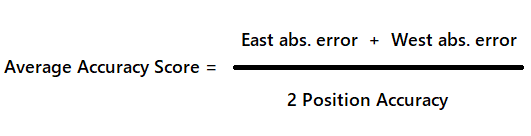

%Now we evaluate each filter using gps normalized accuracy score measure
AVAccScore = zeros(framesNum,1);
WEAccScore = zeros(framesNum,1);
WEGAccScore = zeros(framesNum,1);
KFSAccScore = zeros(framesNum,1);
KFUSAccScore = zeros(framesNum,1);
AWEGAccScore = zeros(framesNum,1);
AKFSAccScore = zeros(framesNum,1);
AKFUSAccScore = zeros(framesNum,1);
FBKFAccScore = zeros(framesNum,1);

for i= 1:framesNum
    [AVAccScore(i), ~, ~] = accuracyScore(GPSe(i), GPSn(i), posAcc(i), XAvg(i), YAvg(i));
    [WEAccScore(i), ~, ~] = accuracyScore(GPSe(i), GPSn(i), posAcc(i), XWs(i), YWs(i));
    [WEGAccScore(i), ~, ~] = accuracyScore(GPSe(i), GPSn(i), posAcc(i), XGWs(i), YGWs(i));
    [KFSAccScore(i), ~, ~] = accuracyScore(GPSe(i), GPSn(i), posAcc(i), kfEast(i), kfNorth(i));
    [KFUSAccScore(i), ~, ~] = accuracyScore(unsyncGPSe(i), unsyncGPSn(i), unsyncPosAcc(i), kfEastU(i), kfNorthU(i));
    [AWEGAccScore(i), ~, ~] = accuracyScore(GPSe(i), GPSn(i), posAcc(i), XAGWs(i), YAGWs(i));
    [AKFSAccScore(i), ~, ~] = accuracyScore(GPSe(i), GPSn(i), posAcc(i), AkfEast(i), AkfNorth(i));
    [AKFUSAccScore(i), ~, ~] = accuracyScore(unsyncGPSe(i), unsyncGPSn(i), unsyncPosAcc(i), AkfEastU(i), AkfNorthU(i));
    [FBKFAccScore(i), ~, ~] = accuracyScore(GPSe(i), GPSn(i), posAcc(i), kfXFrames(i), kfYFrames(i));
end

%Now we plot change in accuracy measure for different approaches (Low accuracy filters)
figure;

plot(timeVector, AVAccScore, '-s');
hold on;
plot(timeVector, WEAccScore, '-x');
plot(timeVector, WEGAccScore, '-o');
plot(timeVector, KFSAccScore, '-*');
plot(timeVector, KFUSAccScore, '--');

legend('Average Estimates Score', 'Weighted Estimates Score', 'Weighted Estimates Score Excluding GPS', 'KF Estimates Score', 'Unsynced KF Estimates Score');
title('Accuracy Score for Non Adaptive filters');
xlabel('Time (s)');
ylabel('accuracyScore');
grid on;
hold off;

%Now we plot change in accuracy measure for different approaches (High accuracy filters)
figure;

plot(timeVector, AWEGAccScore, '-x');
hold on;
plot(timeVector, AKFSAccScore, '-*');
plot(timeVector, AKFUSAccScore, '-s');
plot(timeVector, FBKFAccScore, '-o');

legend('Adaptive Weighted Estimates Score','Adaptive KF Estimates Score', 'Adaptive Unsynced KF Estimates Score', 'Frame-Based KF');
title('Accuracy Score for frame-based and adaptive filters');
xlabel('Time (s)');
ylabel('accuracyScore');
grid on;
hold off;

## Table of comparison for each Fusion technique

In this section, we are going to compare results obtained from different fusion techniques and compare it to the given GPS data as ground truth as well comparing to GPS and including its accuracy using Accuracy Score measure discussed before.

We construct table of comparison includes sensor used, max deviation in local east position, max deviation in local north position, maximum deviation in yaw angle, and average accuracy score.

%To obtain total distance of travel 
totalDist = 0;
for i= 2:framesNum
    deltaEast = GPSe(i) - GPSe(i-1);
    deltaNorth = GPSn(i) - GPSn(i-1);
    dist = sqrt(deltaEast^2 + deltaNorth^2);
    totalDist = totalDist + dist;
end
fprintf('For a route with length = %f ', totalDist)

names = {'Average', 'Weighted Average', 'Weighted average exc. GPS', 'Synced KF', 'unSynced KF', 'Adaptive weighted average Exc. GPS' ,'Adaptive Synced KF', 'Adaptive unSynced KF', 'Adaptive frame based KF'};
FmaxEastDeviation = [max(abs(AEDeltaE)),  max(abs(GWSDeltaE)),   max(abs(WSDeltaE)),   max(abs(kfDeltaE)),   max(abs(kfDeltaEU)),   max(abs(AWADeltaE)),    max(abs(AKFDeltaE)),    max(abs(AkfDeltaEU)),    max(abs(FBkfDeltaEU))];
FmaxNorthDeviation = [max(abs(AEDeltaN)), max(abs(GWSDeltaN)),   max(abs(WSDeltaN)),   max(abs(kfDeltaN)),   max(abs(kfDeltaNU)),   max(abs(AWADeltaN)),    max(abs(AKFDeltaN)),    max(abs(AkfDeltaNU)),    max(abs(FBkfDeltaNU))];
FmaxYawDeviation = [max(abs(AEDeltaYaw)), max(abs(GWSDeltaYaw)), max(abs(WSDeltaYaw)), max(abs(kfDeltaYaw)), max(abs(kfDeltaYawU)), max(abs(AWADeltaYaw)),  max(abs(AKFDeltaYaw)),  max(abs(AkfDeltaYawU)),  max(abs(FBkfDeltaYawU))];
averageAccScore = [mean(AVAccScore),      mean(WEAccScore),      mean(WEGAccScore),    mean(KFSAccScore),    mean(KFUSAccScore),    mean(AWEGAccScore),     mean(AKFSAccScore),     mean(AKFUSAccScore), mean(FBKFAccScore)];
fusionTable = table(names', averageAccScore', FmaxEastDeviation', FmaxNorthDeviation', FmaxYawDeviation','VariableNames',{'Fusion Technique used', 'Average accuracy score', 'Max. deviation in East(m)', 'Max. deviation in North(m)', 'Max. deviation in Yaw(deg)'})